% Import dataset
data = rmmissing(readtable("DatiProject.xlsx"));
head(data);

       Time        GDPC1     PCECTPI    TB3MS      GS10 
    ___________    ______    _______    ______    ______

    30-Jun-1960    3430.1    15.331       3.54    4.5033
    30-Sep-1960    3439.8    15.415       4.23    4.5833
    30-Dec-1960    3517.2    15.435     3.8733    4.4867
    30-Mar-1961    3498.2    15.515     2.9933      4.26
    30-Jun-1961    3515.4    15.574       2.36    3.8333
    30-Sep-1961    3470.3    15.642     2.3067    3.8867
    30-Dec-1961    3493.7    15.671       2.35    3.7867
    30-Mar-1962      3553     15.67     2.3033      3.79



% Data preparation
data.yt = log(data.GDPC1);
data.log_pce = log(data.PCECTPI);
data.T_spread = data.GS10 - data.TB3MS;

% Computing first-differences of yt and PCE logs
delta_yt1 = diff(data.yt);
delta_log_pce = diff(data.log_pce);
head(data)

       Time        GDPC1     PCECTPI    TB3MS      GS10       yt      log_pce    T_spread
    ___________    ______    _______    ______    ______    ______    _______    ________

    30-Jun-1960    3430.1    15.331       3.54    4.5033    8.1403    2.7299      0.9633 
    30-Sep-1960    3439.8    15.415       4.23    4.5833    8.1432    2.7353      0.3533 
    30-Dec-1960    3517.2    15.435     3.8733    4.4867    8.1654    2.7366      0.6134 
    30-Mar-1961    3498.2    15.515     2.9933      4.26      8.16    2.7418      1.2667 
    30-Jun-1961    3515.4    15.574       2.36    3.8333    8.1649    2.7456      1.4733 
    30-Sep-1961    3470.3    15.642     2.3067    3.8867     8.152      2.75        1.58 
    30-

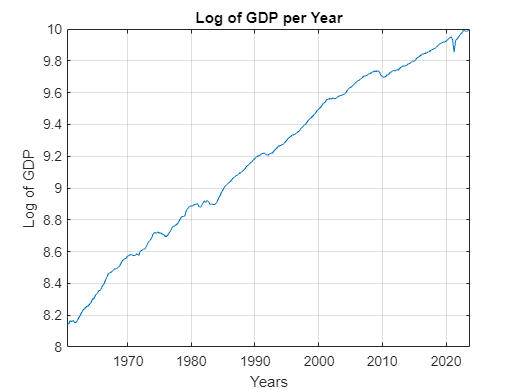

% Plot of the series - Section 1
plot(data.Time, data.yt); title("Log of GDP per Year"); grid on;
ylabel("Log of GDP"); 
xlabel("Years"); 

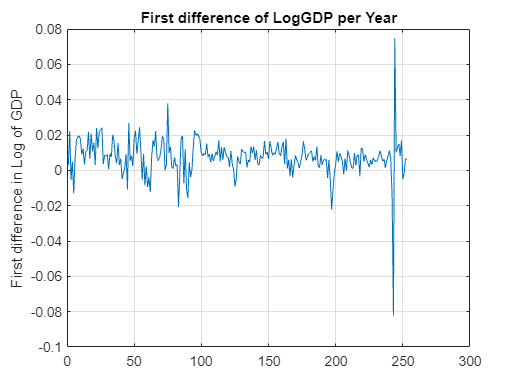


plot(delta_yt1); title("First difference of LogGDP per Year"); grid on;
ylabel("First difference in Log of GDP");

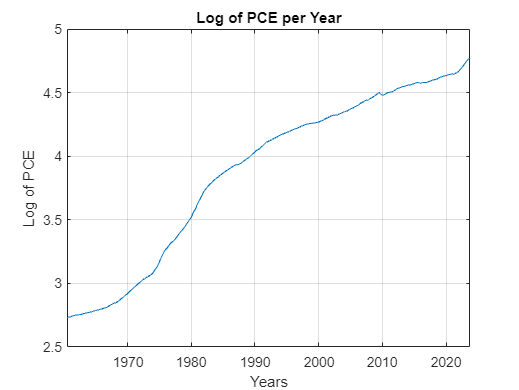


plot(data.Time, data.log_pce); title("Log of PCE per Year"); grid on;
ylabel("Log of PCE"); 
xlabel("Years");

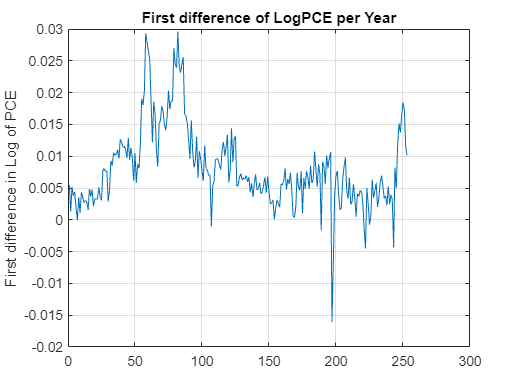


plot(delta_log_pce); title("First difference of LogPCE per Year"); grid on;
ylabel("First difference in Log of PCE");

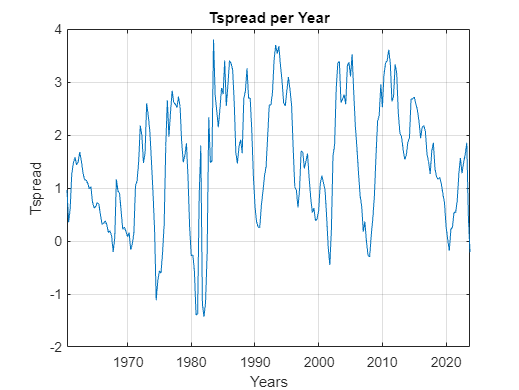


plot(data.Time, data.T_spread); title("Tspread per Year"); grid on;
ylabel("Tspread"); 
xlabel("Years");

% Training set up to Q1 1985
flt = data.Time <= datetime(2018,09,30);

delta_yt = diff(data(flt,:).yt);
delta_log_pce = diff(data(flt,:).log_pce);
dataTspread = data(flt,:).T_spread(2:end,:);

flt_test_set = data.Time > datetime(1985,03,30) & data.Time <= datetime(2018,09,30);

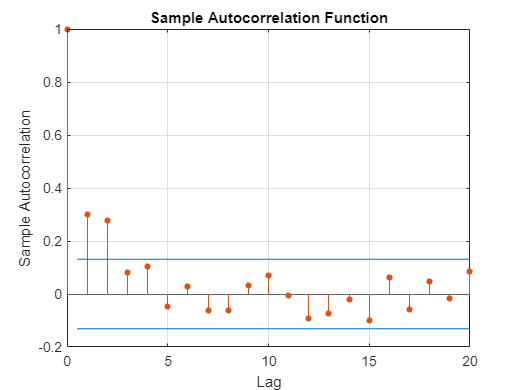

% ACF of VAR(4) series

% ACF delta_yt
autocorr(delta_yt);

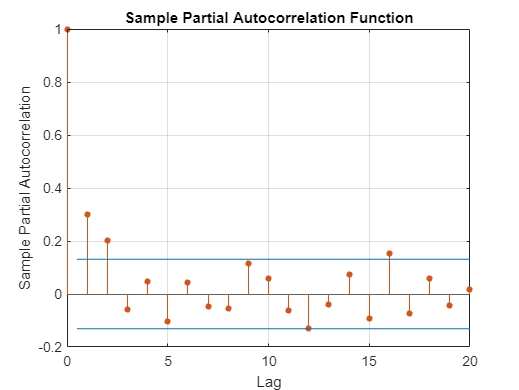

parcorr(delta_yt);

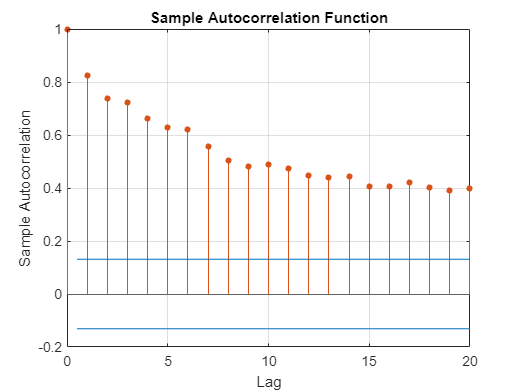


% ACF delta_log_pce
autocorr(delta_log_pce);

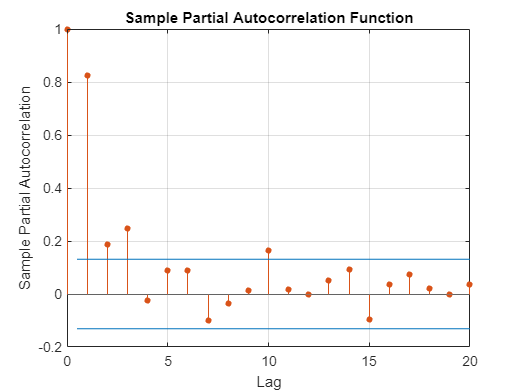

parcorr(delta_log_pce);

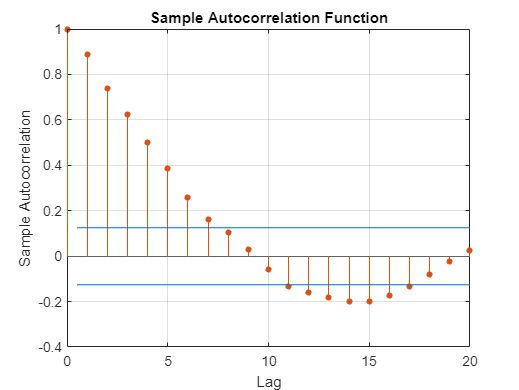


% ACF T_spread
autocorr(data.T_spread);

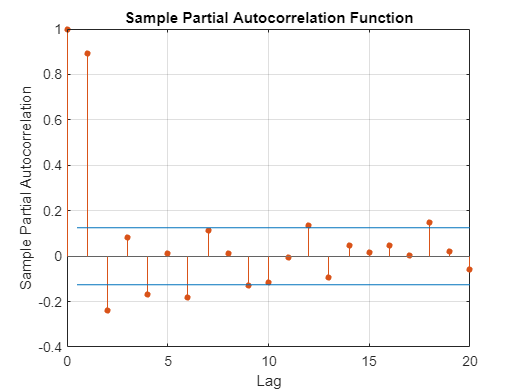

parcorr(data.T_spread);

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant             0              0           NaN             NaN
    Variance    0.00018745     3.1985e-05        5.8605      4.6154e-09

 
    ARIMA(0,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant             0          0             NaN         NaN  
    Variance    0.00018745          0             Inf        

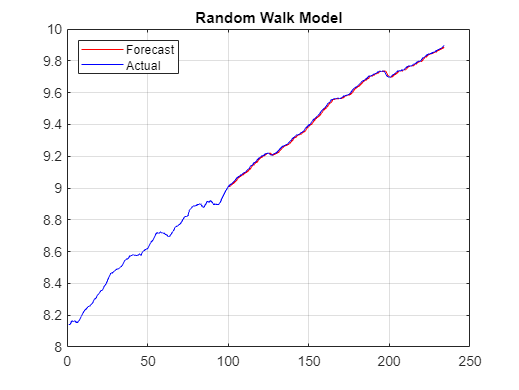

% Random Walk for yt
rw = arima('D', 1, 'Constant', 0);

data_rw = data(flt,:).yt; % considering only yt column
actual_data_rw = data(flt_test_set,:).yt; % extracting real data

fore_rw = computeForecasts(rw, data_rw, data_rw, 'Random Walk Model');

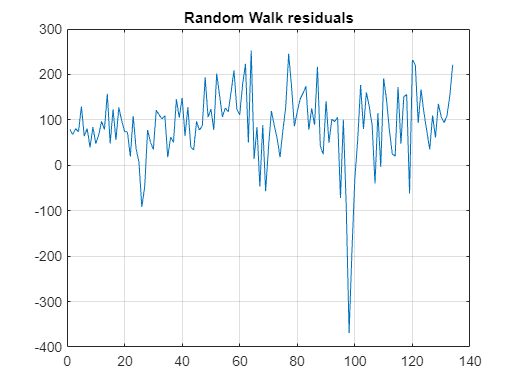

rw_uhat = exp(actual_data_rw) - exp(fore_rw(end-133:end,:));

plot(rw_uhat); 
title('Random Walk residuals');
grid on;

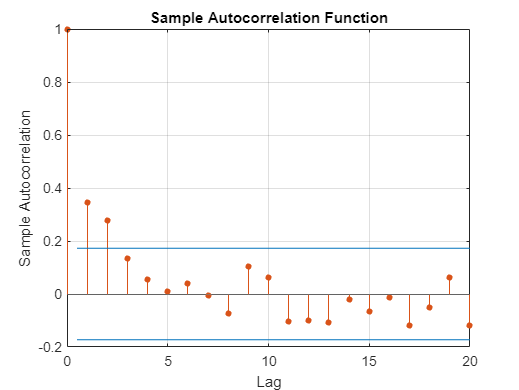


autocorr(rw_uhat);

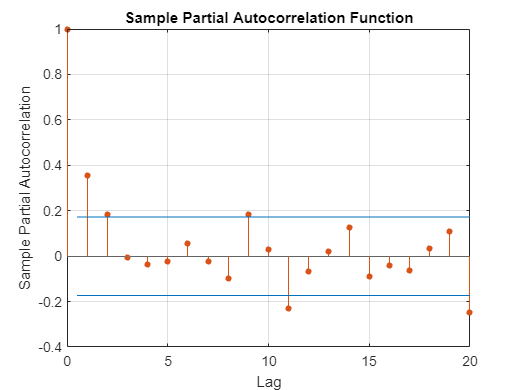

parcorr(rw_uhat);


rmse_rw = sqrt(mean(rw_uhat.^2))

rmse_rw = 119.4383

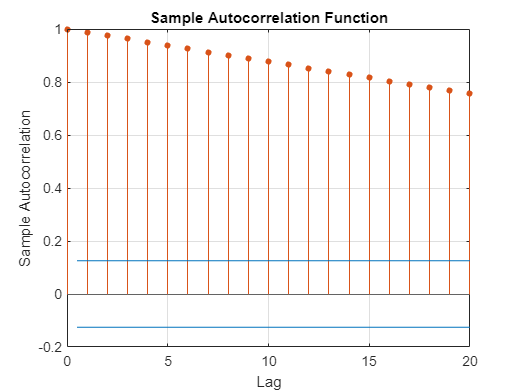

% BONUS
autocorr(data.yt)

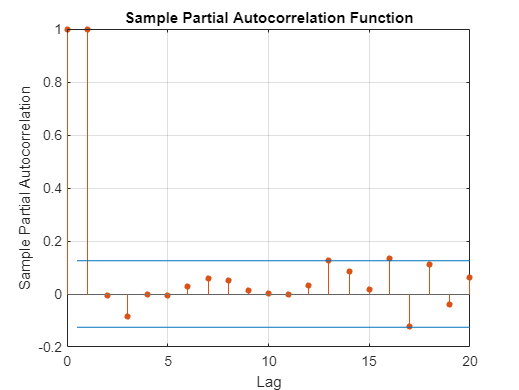

parcorr(data.yt)

% p = 1 looks like the best option

% AIC for p selection da fare

 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     0.0062274       0.001252         4.974      6.5579e-07
    AR{1}          0.27994        0.10702        2.6158       0.0089024
    Variance    0.00010473     1.4181e-05        7.3854      1.5198e-13

 
    ARIMA(1,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    ______

    Constant     0.0062274          0             Inf    

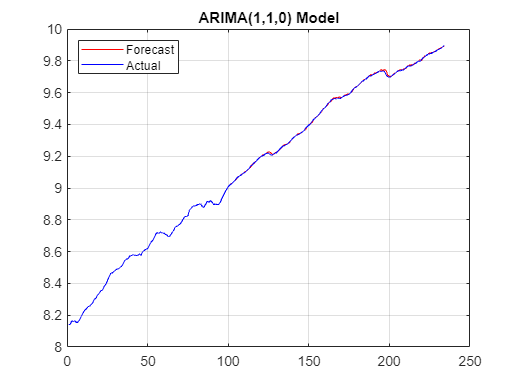

ar_1 = arima(1,1,0);
fore_ar_1 = computeForecasts(ar_1, data_rw, data_rw, 'ARIMA(1,1,0) Model');

ar_1_uhat = exp(actual_data_rw) - exp(fore_ar_1(end-133:end,:));
rmse_ar1d = sqrt(mean(ar_1_uhat.^2))

rmse_ar1d = 82.0392

 
    ARIMA(2,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     0.0052298       0.001291        4.0511      5.0979e-05
    AR{1}          0.21763        0.11269        1.9313        0.053449
    AR{2}          0.19114       0.098897        1.9327        0.053276
    Variance    0.00010085     1.3259e-05        7.6062      2.8235e-14

 
    ARIMA(2,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic    PValue
                __________    _____________    __________    __

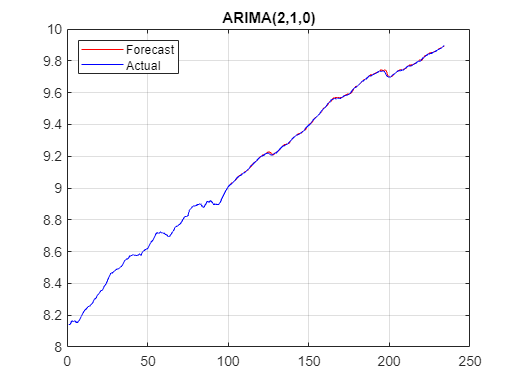

% AR(2) for deltay
fore_ar_2_d = computeForecasts(arima(2,1,0), data_rw, data_rw, 'ARIMA(2,1,0)');

ar_2d_uhat = exp(actual_data_rw) - exp(fore_ar_2_d(end-133:end,:));
rmse_ar2d = sqrt(mean(ar_2d_uhat.^2))

rmse_ar2d = 79.5741

 
    ARIMA(4,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant     0.0053445      0.0014403         3.7107     0.00020665
    AR{1}          0.23589        0.11568         2.0392       0.041428
    AR{2}          0.19569       0.097896          1.999       0.045607
    AR{3}         -0.10291        0.12009       -0.85697        0.39146
    AR{4}         0.069476       0.094763        0.73315        0.46347
    Variance    9.9759e-05     1.3587e-05         7.3425     2.0968e-13

 
    ARIMA(4,1,0) Model (Gaussian Distribution):
 
                  Value       StandardError   

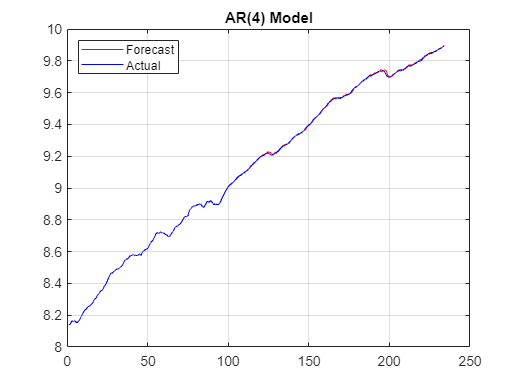

% AR(4) for delta_yt
ar_4 = arima(4,1,0);
actual_delta_yt = diff(data(flt_test_set,:).yt); % actual data of yt used as the test set
fore_ar_4 = computeForecasts(ar_4, data_rw, data_rw, 'AR(4) Model');

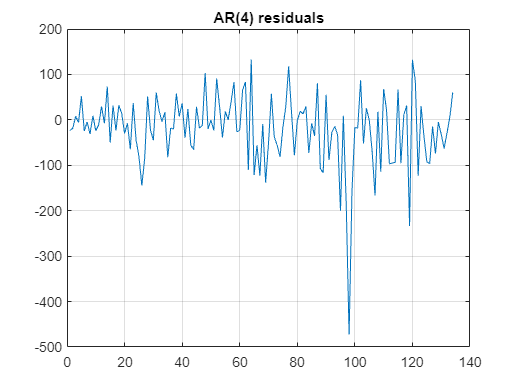

ar_4_uhat = exp(actual_data_rw) - exp(fore_ar_4(end-133:end,:));

plot(ar_4_uhat);
title('AR(4) residuals');
grid on;

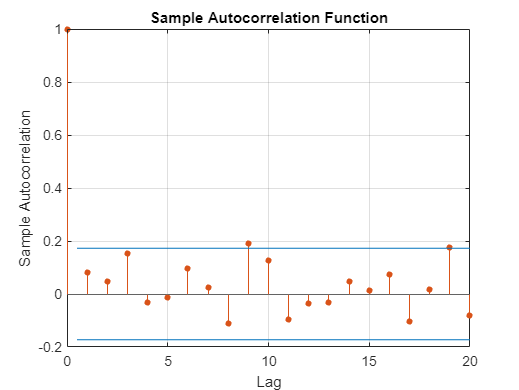


autocorr(ar_4_uhat);

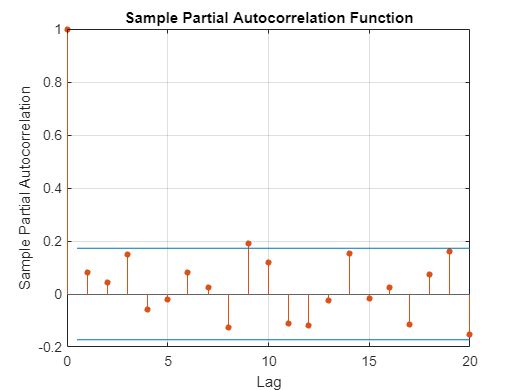

parcorr(ar_4_uhat);


rmse_ar_4 = sqrt(mean(ar_4_uhat.^2))

rmse_ar_4 = 80.3807

% VAR(4) (using our function)
data_var = [delta_yt delta_log_pce dataTspread]

data_var =     0.0028    0.0055    0.3533
    0.0222    0.0013    0.6134
   -0.0054    0.0052    1.2667
    0.0049    0.0038    1.4733
   -0.0129    0.0044    1.5800
    0.0067    0.0019    1.4367
    0.0168   -0.0001    1.4867
    0.0190    0.0036    1.6767
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934


var_4 = varm(3,4)

var_4 =   varm with properties:

     Description: "3-Dimensional VAR(4) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 4
        Constant: [3×1 vector of NaNs]
              AR: {3×3 matrices of NaNs} at lags [1 2 3 ... and 1 more]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix of NaNs]

%fore_var_4 = computeForecasts(var_4, data_var, data_var, 'VAR(4) Model') --> call to the function 

% VAR(4) with Rolling window on 100 observation with VAR(4)
fore_var_4 = [delta_yt delta_log_pce dataTspread];
k = 1;
j = 100;

for i = 1:134
    fore_var_4(100+i,1:3) = forecast(estimate(varm(3,4), data_var(k:j,:)), 1, data_var(k:j,:));
    
    k = k + 1;
    j = j + 1;
end

% Transform VAR(4) predictions to log of GDP forecasts
var_4_yt = data_rw

var_4_yt =     8.1403
    8.1432
    8.1654
    8.1600
    8.1649
    8.1520
    8.1587
    8.1756
    8.1946
    8.2140


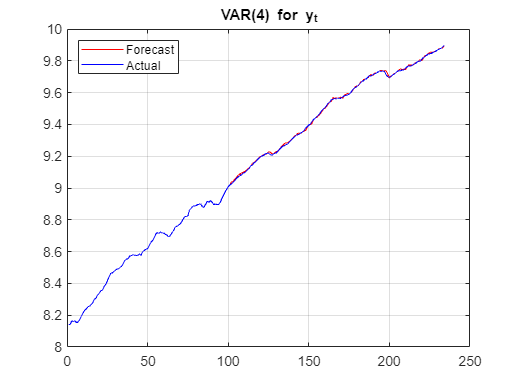


for i = length(var_4_yt)-133:length(var_4_yt)
    var_4_yt(i) = data_rw(i-1) + fore_var_4(i-1,1);
end

plot(var_4_yt, Color="red"); hold on;
plot(data_rw, Color="blue"); hold off;
title('VAR(4) for y_t');
legend("Forecast", "Actual", 'Location','northwest');
grid on;


var_4_uhat = exp(actual_data_rw) - exp(var_4_yt(end-133:end,:));
rmse_var_4 = sqrt(mean(var_4_uhat.^2))

rmse_var_4 = 93.3439

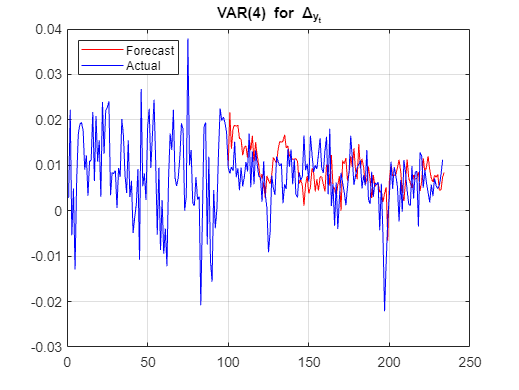

% Plotting the 3 series

plot(fore_var_4(:,1), Color="red"); hold on;
plot(data_var(:,1), Color="blue"); hold off;
title('VAR(4) for \Delta_{y_t}');
legend("Forecast", "Actual", 'Location','northwest');
grid on;

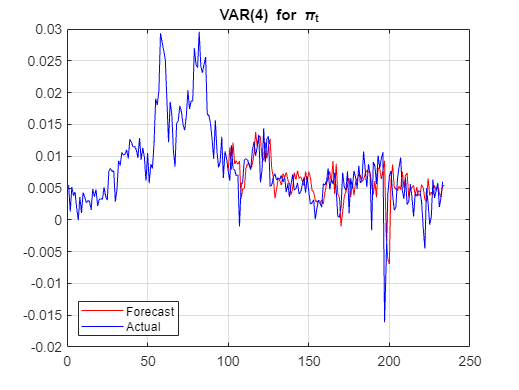


plot(fore_var_4(:,2), Color="red"); hold on;
plot(data_var(:,2), Color="blue"); hold off;
title('VAR(4) for \pi_t');
legend("Forecast","Actual", 'Location','southwest');
grid on;

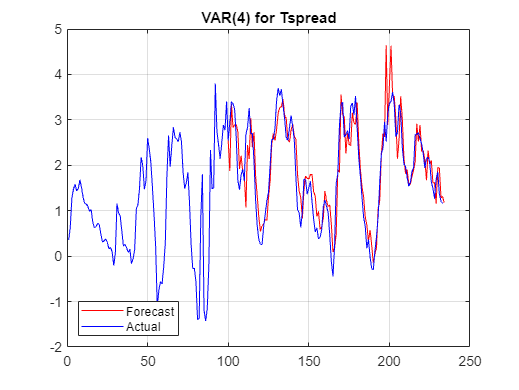


plot(fore_var_4(:,3), Color="red"); hold on;
plot(data_var(:,3), Color="blue"); hold off;
title('VAR(4) for Tspread');
legend( "Forecast","Actual", 'Location','southwest');
grid on;

% Residuals for the 3 series, RMSE for deltaY

var4_uhat(:,1) = exp(data_var(end-133:end,1)) - exp(fore_var_4(end-133:end,1));
var4_uhat(:,2) = exp(data_var(end-133:end,2)) - exp(fore_var_4(end-133:end,2));
var4_uhat(:,3) = exp(data_var(end-133:end,3)) - exp(fore_var_4(end-133:end,3));

rmse_var4_yd = sqrt(mean(var4_uhat(:,1).^2))

rmse_var4_yd = 0.0061

rmse_var4_pi = sqrt(mean(var4_uhat(:,2).^2))

rmse_var4_pi = 0.0025

rmse_var4_tspread = sqrt(mean(var4_uhat(:,3).^2))

rmse_var4_tspread = 10.5670

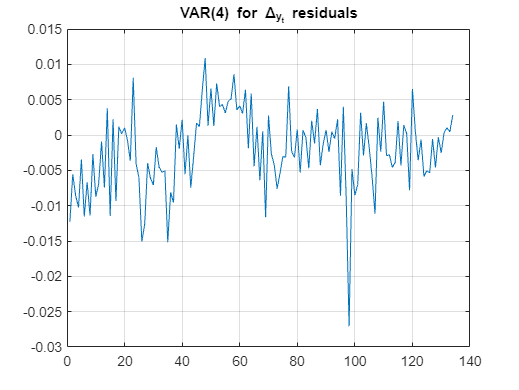


% Plots of residuals and their ACF PCF

plot(var4_uhat(:,1));
title('VAR(4) for \Delta_{y_t} residuals')
grid on;

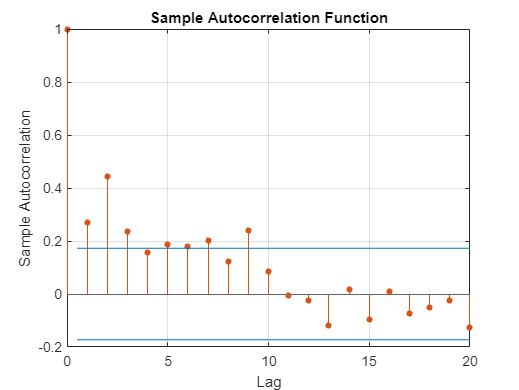

autocorr(var4_uhat(:,1));

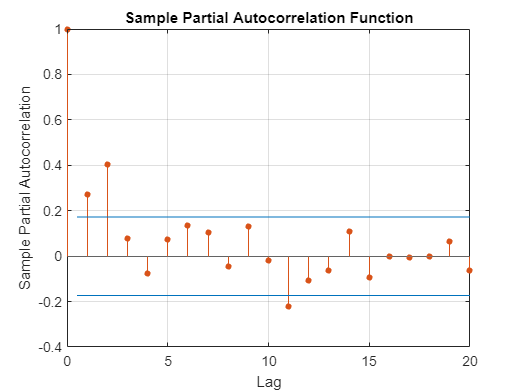

parcorr(var4_uhat(:,1));

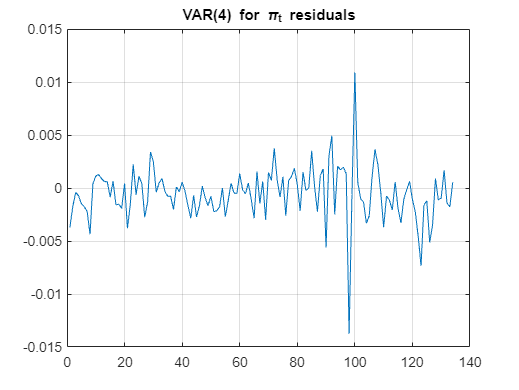

plot(var4_uhat(:,2));
title('VAR(4) for \pi_t residuals');
grid on;

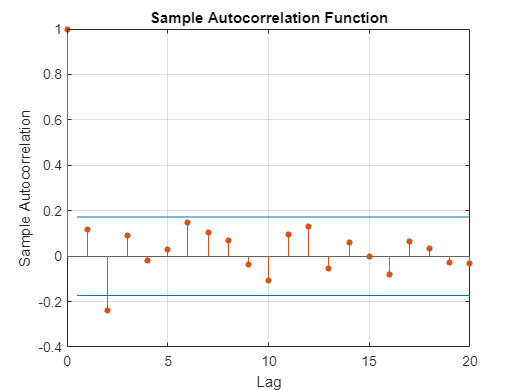

autocorr(var4_uhat(:,2));

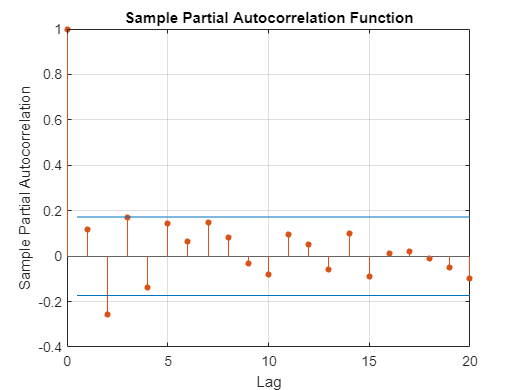

parcorr(var4_uhat(:,2));

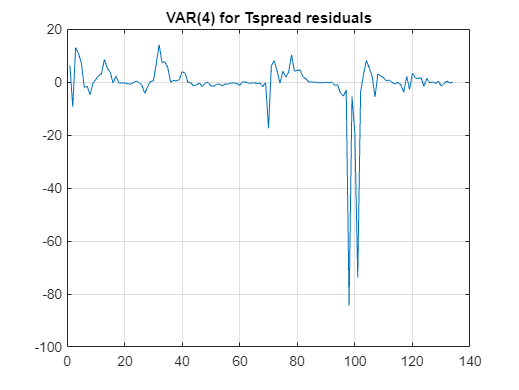

plot(var4_uhat(:,3));
title('VAR(4) for Tspread residuals')
grid on;

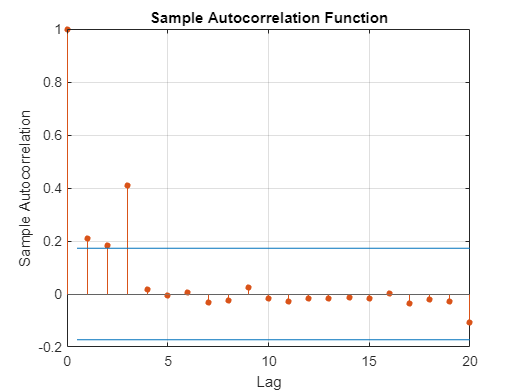

autocorr(var4_uhat(:,3))

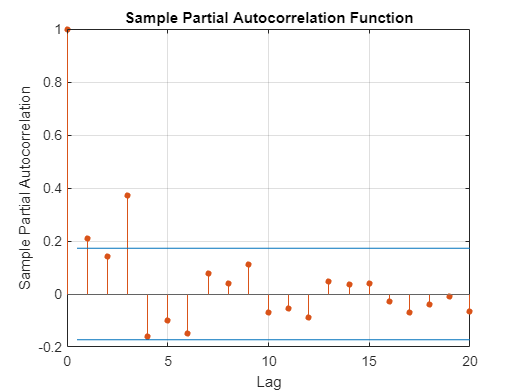

parcorr(var4_uhat(:,3))

% AIC for p selection
for pp = 1:12
    m1 = estimate(varm(3,pp), data_var(1:100,:));
    tmp = summarize(m1);
    IC(pp,:) = [tmp.AIC];
end
disp(IC)

   1.0e+03 *

   -1.2879
   -1.2802
   -1.2690
   -1.2768
   -1.2676
   -1.2525
   -1.2463
   -1.2350
   -1.2119
   -1.2154
   -1.2068
   -1.1901



[minaic,popt] = min(IC)

minaic = -1.2879e+03

popt = 1

num = (1:12)'

num =      1
     2
     3
     4
     5
     6
     7
     8
     9
    10


AIC = [num IC] 

AIC = 1.0e+03 *

    0.0010   -1.2879
    0.0020   -1.2802
    0.0030   -1.2690
    0.0040   -1.2768
    0.0050   -1.2676
    0.0060   -1.2525
    0.0070   -1.2463
    0.0080   -1.2350
    0.0090   -1.2119
    0.0100   -1.2154


ticks = (1:12)

ticks =      1     2     3     4     5     6     7     8     9    10    11    12


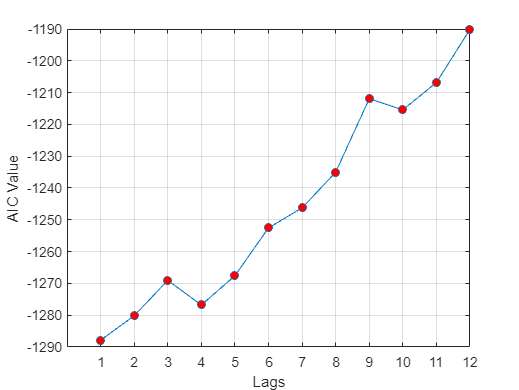

plot(num, IC, '-o', 'MarkerFaceColor','red');
ylabel("AIC Value"); 
xlabel("Lags");
xticks(ticks);
grid on;

% VAR(1)

data_var = [delta_yt delta_log_pce dataTspread]

data_var =     0.0028    0.0055    0.3533
    0.0222    0.0013    0.6134
   -0.0054    0.0052    1.2667
    0.0049    0.0038    1.4733
   -0.0129    0.0044    1.5800
    0.0067    0.0019    1.4367
    0.0168   -0.0001    1.4867
    0.0190    0.0036    1.6767
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934


var_1 = varm(3,1)

var_1 =   varm with properties:

     Description: "3-Dimensional VAR(1) Model"
     SeriesNames: "Y1"  "Y2"  "Y3" 
       NumSeries: 3
               P: 1
        Constant: [3×1 vector of NaNs]
              AR: {3×3 matrix of NaNs} at lag [1]
           Trend: [3×1 vector of zeros]
            Beta: [3×0 matrix]
      Covariance: [3×3 matrix of NaNs]

fore_var_1 = computeForecasts(var_1, data_var, data_var, 'VAR(1) Model')

fore_var_1 =     0.0028    0.0055    0.3533
    0.0222    0.0013    0.6134
   -0.0054    0.0052    1.2667
    0.0049    0.0038    1.4733
   -0.0129    0.0044    1.5800
    0.0067    0.0019    1.4367
    0.0168   -0.0001    1.4867
    0.0190    0.0036    1.6767
    0.0194    0.0011    1.5133
    0.0177    0.0043    1.2934


var_1_yt = data_rw

var_1_yt =     8.1403
    8.1432
    8.1654
    8.1600
    8.1649
    8.1520
    8.1587
    8.1756
    8.1946
    8.2140


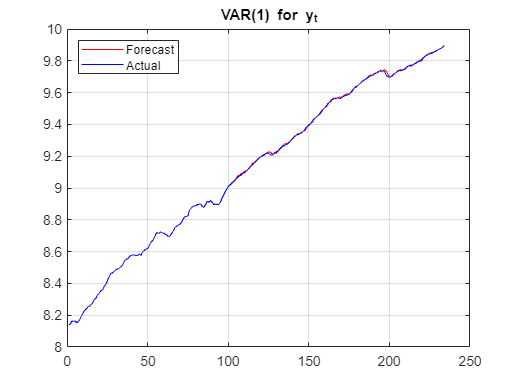


for i = length(var_1_yt)-133:length(var_1_yt)
    var_1_yt(i) = data_rw(i-1) + fore_var_1(i-1,1);
end

plot(var_1_yt, Color="red"); hold on;
plot(data_rw, Color="blue"); hold off;
title('VAR(1) for y_t');
legend("Forecast", "Actual", 'Location','northwest');
grid on;


var_1_uhat = exp(actual_data_rw) - exp(var_1_yt(end-133:end,:));
rmse_var_1 = sqrt(mean(var_1_uhat.^2))

rmse_var_1 = 84.9931

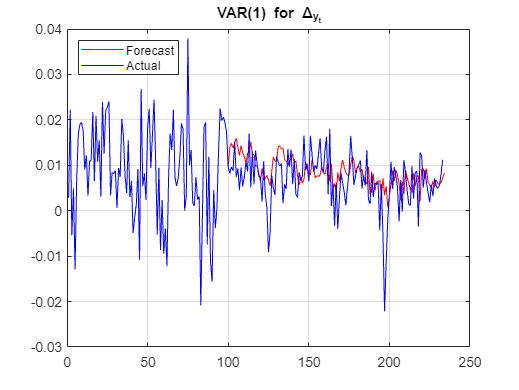


% Plotting the 3 series

plot(fore_var_1(:,1), Color="red"); hold on;
plot(data_var(:,1), Color="blue"); hold off;
title('VAR(1) for \Delta_{y_t}');
legend("Forecast", "Actual", 'Location','northwest');
grid on;

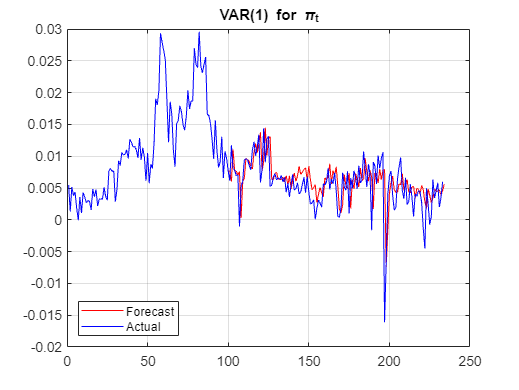


plot(fore_var_1(:,2), Color="red"); hold on;
plot(data_var(:,2), Color="blue"); hold off;
title('VAR(1) for \pi_t');
legend("Forecast","Actual", 'Location','southwest');
grid on;

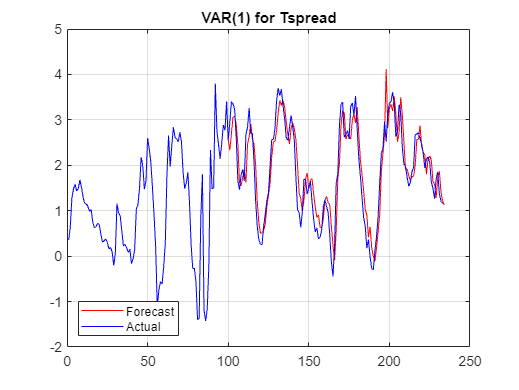


plot(fore_var_1(:,3), Color="red"); hold on;
plot(data_var(:,3), Color="blue"); hold off;
title('VAR(1) for Tspread');
legend( "Forecast","Actual", 'Location','southwest');
grid on;


% Residuals for the 3 series, RMSE for deltaY

var1_uhat(:,1) = exp(data_var(end-133:end,1)) - exp(fore_var_4(end-133:end,1));
var1_uhat(:,2) = exp(data_var(end-133:end,2)) - exp(fore_var_4(end-133:end,2));
var1_uhat(:,3) = exp(data_var(end-133:end,3)) - exp(fore_var_4(end-133:end,3));

rmse_var1_yd = sqrt(mean(var1_uhat(:,1).^2))

rmse_var1_yd = 0.0061

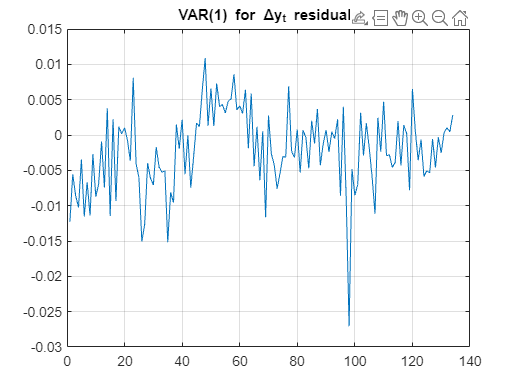

plot(var1_uhat(:,1));
title('VAR(1) for \Deltay_t residuals')
grid on;

autocorr(var1_uhat(:,1));

parcorr(var1_uhat(:,1));

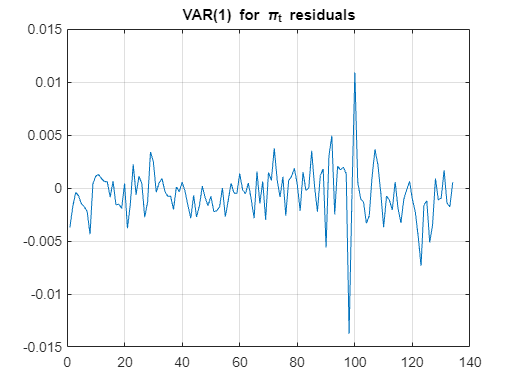

plot(var1_uhat(:,2));
title('VAR(1) for \pi_t residuals');
grid on;

autocorr(var1_uhat(:,2));

parcorr(var1_uhat(:,2));

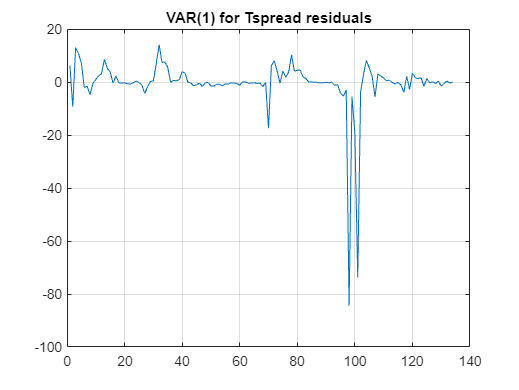

plot(var1_uhat(:,3));
title('VAR(1) for Tspread residuals')
grid on;

autocorr(var1_uhat(:,3))

parcorr(var1_uhat(:,3))

% AR-X + PC


data_factors = readtable('DatiProject.xlsx', 'Sheet', 'DataForFactors');

Time = (datetime(1961,03,30):calquarters(1):datetime(1985,12,30))';
flt_pc = data_factors.Time <= datetime(2018,09,30);
data_factors = removevars(data_factors,{'Time'});
head(data_factors);

      PCECC96        PCDGx         PCESVx        PCNDx         GPDIC1         FPIx       Y033RC1Q027SBEAx      PNFIx         PRFIx       A014RE1Q156NBEA      GCEC1       A823RL1Q225SBEA     FGRECPTx        SLCEx        EXPGSC1       IMPGSC1        DPIC96         OUTNFB        OUTBS         OUTMS        INDPRO       IPFINAL      IPCONGD        IPMAT       IPDMAT        IPNMAT      IPDCONGD     IPB51110SQ     IPNCONGD      IPBUSEQ      IPB51220SQ     TCU

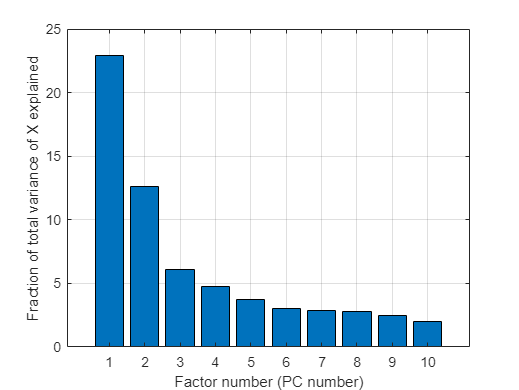


factors = table2array(data_factors);
%(1:100)
factors_s = zscore(factors(1:100,:)); % standardize
[coeff,F,cc, vv, explained, cg] = pca(factors_s);
bar(1:10,explained(1:10));
xlabel('Factor number (PC number)');
ylabel('Fraction of total variance of X explained');
grid on;



factors_fore = table2array(data_factors(flt_pc,:));

factor_all = zscore(factors)

factor_all =     0.3448    0.1982    0.9996   -0.2748   -1.8233    0.0578    0.6386    0.7313   -0.4977   -0.6388    0.3965    0.5308   -1.1473   -0.5983    2.1024   -0.1034   -0.8629   -0.7273   -0.7686   -0.8177   -2.5845    0.4277    0.4069   -4.9582   -5.3433   -0.0265   -0.0916   -0.5192    0.9874    0.3546    0.5872    1.1443    0.2329   -0.5846   -0.6408   -0.5473   -0.1258   -0.6866   -1.1177    0.9082   -0.5353   -0.5018    0.3918   -0.5788   -0.5822   -0.1834   -0.0333   -1.2112    0.0830    0.4280
   -0.9483   -2.0126    0.7422   -0.0033    0.5448   -0.9636   -0.4876   -0.6831   -0.7150    0.5358   -1.3066   -0.7871   -0.1608   -1.2804   -1.7004   -1.0894   -0.0225   -0.8329   -0.5860   -0.5455   -0.0596   -0.9442   -0.9227    0.7484    0.9094   -0.7176   -1.4504   -2.0442    0.1671   -1.0833    0.6595    1.0973    0.1488   -0.0946   -0.2861   -0.0278    0.2806   -0.2680   -0.0912    0.1322   -1.0274    0.7105    0.4551   -0.2835    0.0154   -0.1221    0.7311    0.0358   -0.

[coeff_all,F_all,cca, vsv, explained_all, cgsda] = pca(factor_all);

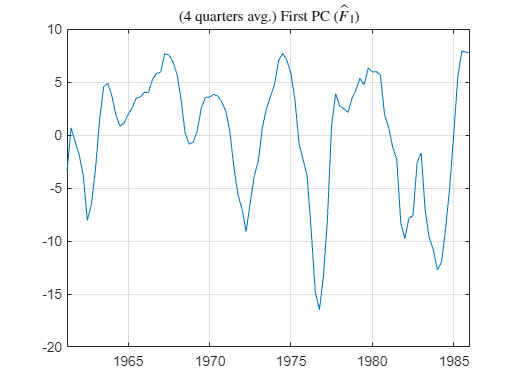

plot(Time,movmean(F(:,1),4)); title('(4 quarters avg.) First PC ($\hat{F}_{1})$','Interpreter','latex'); grid on;

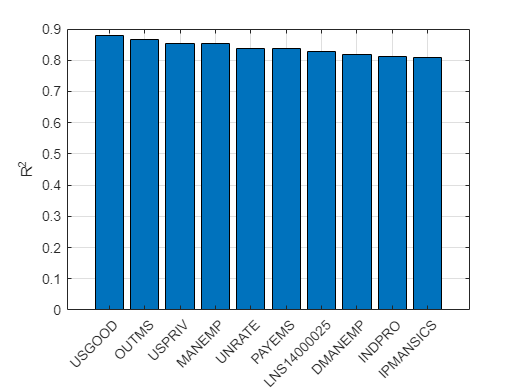

K = size(factors_s,2);
for kk=1:K
    res = fitlm(factors_s(:,kk),F(:,1));
    R2(kk,1) = res.Rsquared.Ordinary;
    res = fitlm(factors_s(:,kk),F(:,2));
    R2(kk,2) = res.Rsquared.Ordinary;
    res = fitlm(factors_s(:,kk),F(:,3));
    R2(kk,3) = res.Rsquared.Ordinary;
end
[~,id] = sort(R2(:,1),1,"descend");
bar(1:10, R2(id(1:10),1)'); xticks(1:10); xticklabels(data_factors.Properties.VariableNames(id(1:10))); xtickangle(45); ylabel('R^2'); grid on;

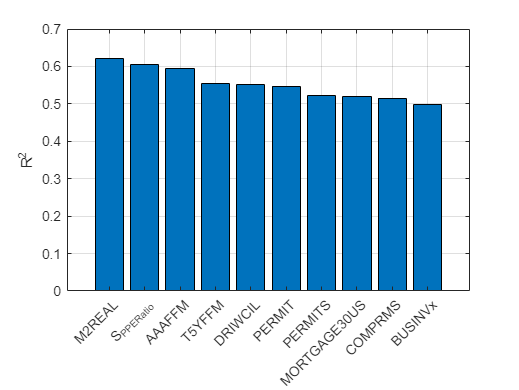

[~,id] = sort(R2(:,2),1,"descend");
bar(1:10, R2(id(1:10),2)'); xticks(1:10); xticklabels(data_factors.Properties.VariableNames(id(1:10))); xtickangle(45); 
ylabel('R^2')
grid on;

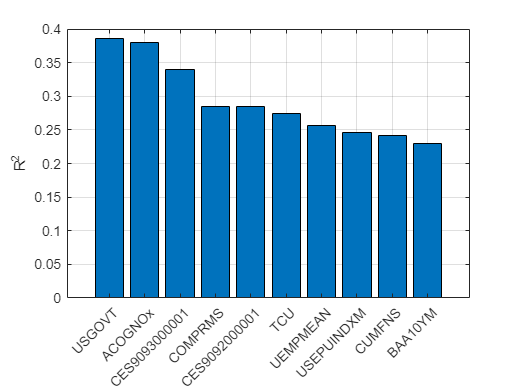

[~,id] = sort(R2(:,3),1,"descend");
bar(1:10, R2(id(1:10),3)'); xticks(1:10); xticklabels(data_factors.Properties.VariableNames(id(1:10))); xtickangle(45)
ylabel('R^2')
grid on;

% AR-X estimation giusto
w_start = 1;
w_size = 100;
n_fore = 134;
i = 1

i = 1

fore_ar_x = delta_yt;
while i < n_fore

    yT = delta_yt(w_start:w_size,:); % y(t)
    factor_100 = F_all(w_start:w_size,1) 
    ar_x = estimate(varm(1,4), yT, 'X', factor_100, 'Display','off')
    fore_ar_x(100+i) = forecast(ar_x, 1, yT, "X", factor_100(end)); % with F at time t-1

    i = i + 1;
    w_start = w_start + 1;
    w_size = w_size + 1;
end

factor_100 =    -3.0151
   -2.9175
    8.5111
   -3.6155
   -7.2841
   -9.3931
   -6.9985
    2.6676
    5.6688
    6.7556


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0107913
              AR: {-0.17792 0.033925 -0.13715 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000967291]
      Covariance: 8.83788e-05

factor_100 =    -2.9175
    8.5111
   -3.6155
   -7.2841
   -9.3931
   -6.9985
    2.6676
    5.6688
    6.7556
    4.3511


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0106441
              AR: {-0.154226 0.0233068 -0.107769 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000902786]
      Covariance: 8.66512e-05

factor_100 =     8.5111
   -3.6155
   -7.2841
   -9.3931
   -6.9985
    2.6676
    5.6688
    6.7556
    4.3511
    2.5438


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0105524
              AR: {-0.14713 0.0224614 -0.101199 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000899547]
      Covariance: 8.6621e-05

factor_100 =    -3.6155
   -7.2841
   -9.3931
   -6.9985
    2.6676
    5.6688
    6.7556
    4.3511
    2.5438
    0.2479


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0102956
              AR: {-0.16811 0.047766 -0.109337 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000936187]
      Covariance: 8.44137e-05

factor_100 =    -7.2841
   -9.3931
   -6.9985
    2.6676
    5.6688
    6.7556
    4.3511
    2.5438
    0.2479
   -0.0040


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0101754
              AR: {-0.17381 0.0493747 -0.0903637 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000925603]
      Covariance: 8.43766e-05

factor_100 =    -9.3931
   -6.9985
    2.6676
    5.6688
    6.7556
    4.3511
    2.5438
    0.2479
   -0.0040
    1.2286


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0100185
              AR: {-0.173529 0.0435437 -0.0892998 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000913503]
      Covariance: 8.39185e-05

factor_100 =    -6.9985
    2.6676
    5.6688
    6.7556
    4.3511
    2.5438
    0.2479
   -0.0040
    1.2286
    4.5795


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0100451
              AR: {-0.179141 0.0380731 -0.0925661 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000916766]
      Covariance: 8.35657e-05

factor_100 =     2.6676
    5.6688
    6.7556
    4.3511
    2.5438
    0.2479
   -0.0040
    1.2286
    4.5795
    3.1611


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0100438
              AR: {-0.179882 0.0383674 -0.0933924 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000918955]
      Covariance: 8.35796e-05

factor_100 =     5.6688
    6.7556
    4.3511
    2.5438
    0.2479
   -0.0040
    1.2286
    4.5795
    3.1611
    2.6387


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0100316
              AR: {-0.174781 0.0386502 -0.0963681 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000905293]
      Covariance: 8.37177e-05

factor_100 =     6.7556
    4.3511
    2.5438
    0.2479
   -0.0040
    1.2286
    4.5795
    3.1611
    2.6387
    4.1231


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0099052
              AR: {-0.168458 0.0409498 -0.0940116 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000891318]
      Covariance: 8.37431e-05

factor_100 =     4.3511
    2.5438
    0.2479
   -0.0040
    1.2286
    4.5795
    3.1611
    2.6387
    4.1231
    3.8570


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00983937
              AR: {-0.164671 0.0399815 -0.0923689 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000887927]
      Covariance: 8.37454e-05

factor_100 =     2.5438
    0.2479
   -0.0040
    1.2286
    4.5795
    3.1611
    2.6387
    4.1231
    3.8570
    5.1410


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00983984
              AR: {-0.167242 0.0417463 -0.0938118 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000891242]
      Covariance: 8.36449e-05

factor_100 =     0.2479
   -0.0040
    1.2286
    4.5795
    3.1611
    2.6387
    4.1231
    3.8570
    5.1410
    2.0446


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00957909
              AR: {-0.159492 0.0435821 -0.0827463 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000864074]
      Covariance: 8.26911e-05

factor_100 =    -0.0040
    1.2286
    4.5795
    3.1611
    2.6387
    4.1231
    3.8570
    5.1410
    2.0446
    8.3330


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00970066
              AR: {-0.160442 0.0446677 -0.0837402 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000871417]
      Covariance: 8.30543e-05

factor_100 =     1.2286
    4.5795
    3.1611
    2.6387
    4.1231
    3.8570
    5.1410
    2.0446
    8.3330
    6.3512


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00967512
              AR: {-0.158655 0.0289026 -0.084381 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000875898]
      Covariance: 8.20164e-05

factor_100 =     4.5795
    3.1611
    2.6387
    4.1231
    3.8570
    5.1410
    2.0446
    8.3330
    6.3512
    5.3043


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00975329
              AR: {-0.167794 0.0354617 -0.0893266 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000882206]
      Covariance: 8.21397e-05

factor_100 =     3.1611
    2.6387
    4.1231
    3.8570
    5.1410
    2.0446
    8.3330
    6.3512
    5.3043
    8.7143


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00974712
              AR: {-0.169564 0.0326305 -0.0890778 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000881921]
      Covariance: 8.20752e-05

factor_100 =     2.6387
    4.1231
    3.8570
    5.1410
    2.0446
    8.3330
    6.3512
    5.3043
    8.7143
    7.7112


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00976652
              AR: {-0.166302 0.0346043 -0.0827837 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000879012]
      Covariance: 8.18073e-05

factor_100 =     4.1231
    3.8570
    5.1410
    2.0446
    8.3330
    6.3512
    5.3043
    8.7143
    7.7112
    3.7445


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00966629
              AR: {-0.147043 0.0259778 -0.0797155 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000863675]
      Covariance: 7.97109e-05

factor_100 =     3.8570
    5.1410
    2.0446
    8.3330
    6.3512
    5.3043
    8.7143
    7.7112
    3.7445
    1.1813


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00964951
              AR: {-0.148648 0.026173 -0.078951 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000862749]
      Covariance: 7.97559e-05

factor_100 =     5.1410
    2.0446
    8.3330
    6.3512
    5.3043
    8.7143
    7.7112
    3.7445
    1.1813
   -0.1078


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00960416
              AR: {-0.144971 0.0110389 -0.0656603 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000850894]
      Covariance: 7.88423e-05

factor_100 =     2.0446
    8.3330
    6.3512
    5.3043
    8.7143
    7.7112
    3.7445
    1.1813
   -0.1078
   -3.7142


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00988806
              AR: {-0.182439 0.00766882 -0.0927874 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000894989]
      Covariance: 7.68351e-05

factor_100 =     8.3330
    6.3512
    5.3043
    8.7143
    7.7112
    3.7445
    1.1813
   -0.1078
   -3.7142
    0.1349


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0103338
              AR: {-0.217357 -0.00893018 -0.0886148 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000927117]
      Covariance: 7.51795e-05

factor_100 =     6.3512
    5.3043
    8.7143
    7.7112
    3.7445
    1.1813
   -0.1078
   -3.7142
    0.1349
    3.5325


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0100117
              AR: {-0.198562 0.00554457 -0.0807173 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000898294]
      Covariance: 7.51024e-05

factor_100 =     5.3043
    8.7143
    7.7112
    3.7445
    1.1813
   -0.1078
   -3.7142
    0.1349
    3.5325
    4.7653


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0100197
              AR: {-0.203933 0.00361937 -0.0779725 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000910529]
      Covariance: 7.51955e-05

factor_100 =     8.7143
    7.7112
    3.7445
    1.1813
   -0.1078
   -3.7142
    0.1349
    3.5325
    4.7653
    4.2100


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00973891
              AR: {-0.19129 0.0113624 -0.0932037 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000909656]
      Covariance: 7.7404e-05

factor_100 =     7.7112
    3.7445
    1.1813
   -0.1078
   -3.7142
    0.1349
    3.5325
    4.7653
    4.2100
    4.3592


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00964023
              AR: {-0.185402 0.012754 -0.0902312 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000920988]
      Covariance: 7.77744e-05

factor_100 =     3.7445
    1.1813
   -0.1078
   -3.7142
    0.1349
    3.5325
    4.7653
    4.2100
    4.3592
    3.5261


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00970171
              AR: {-0.171337 0.00519812 -0.0881573 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000875807]
      Covariance: 7.84736e-05

factor_100 =     1.1813
   -0.1078
   -3.7142
    0.1349
    3.5325
    4.7653
    4.2100
    4.3592
    3.5261
    4.8613


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00966698
              AR: {-0.169603 0.00550882 -0.0875657 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000873489]
      Covariance: 7.84649e-05

factor_100 =    -0.1078
   -3.7142
    0.1349
    3.5325
    4.7653
    4.2100
    4.3592
    3.5261
    4.8613
    3.8201


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00948938
              AR: {-0.163825 0.000547124 -0.0803403 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000865089]
      Covariance: 7.87456e-05

factor_100 =    -3.7142
    0.1349
    3.5325
    4.7653
    4.2100
    4.3592
    3.5261
    4.8613
    3.8201
    3.0431


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00927563
              AR: {-0.146158 0.00334106 -0.0653148 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000820734]
      Covariance: 7.84616e-05

factor_100 =     0.1349
    3.5325
    4.7653
    4.2100
    4.3592
    3.5261
    4.8613
    3.8201
    3.0431
    0.2257


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0091709
              AR: {-0.142011 0.00491758 -0.0673713 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000798234]
      Covariance: 7.83698e-05

factor_100 =     3.5325
    4.7653
    4.2100
    4.3592
    3.5261
    4.8613
    3.8201
    3.0431
    0.2257
   -1.7509


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00915805
              AR: {-0.137782 0.00902227 -0.0689678 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000793371]
      Covariance: 7.83747e-05

factor_100 =     4.7653
    4.2100
    4.3592
    3.5261
    4.8613
    3.8201
    3.0431
    0.2257
   -1.7509
   -7.3719


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00914004
              AR: {-0.134563 0.0166153 -0.0579169 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000783268]
      Covariance: 7.8298e-05

factor_100 =     4.2100
    4.3592
    3.5261
    4.8613
    3.8201
    3.0431
    0.2257
   -1.7509
   -7.3719
   -6.2290


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00901787
              AR: {-0.124979 0.0199772 -0.0624645 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000766715]
      Covariance: 7.83411e-05

factor_100 =     4.3592
    3.5261
    4.8613
    3.8201
    3.0431
    0.2257
   -1.7509
   -7.3719
   -6.2290
   -4.5480


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00894538
              AR: {-0.111935 0.0155744 -0.063835 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000756811]
      Covariance: 7.80995e-05

factor_100 =     3.5261
    4.8613
    3.8201
    3.0431
    0.2257
   -1.7509
   -7.3719
   -6.2290
   -4.5480
   -7.9349


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00903079
              AR: {-0.120465 0.0208886 -0.068329 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000769159]
      Covariance: 7.80074e-05

factor_100 =     4.8613
    3.8201
    3.0431
    0.2257
   -1.7509
   -7.3719
   -6.2290
   -4.5480
   -7.9349
    2.5301


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00936522
              AR: {-0.133119 0.00924719 -0.0581634 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000791527]
      Covariance: 7.6741e-05

factor_100 =     3.8201
    3.0431
    0.2257
   -1.7509
   -7.3719
   -6.2290
   -4.5480
   -7.9349
    2.5301
    2.2290


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00967808
              AR: {-0.162655 0.00763046 -0.0659138 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000823839]
      Covariance: 7.58778e-05

factor_100 =     3.0431
    0.2257
   -1.7509
   -7.3719
   -6.2290
   -4.5480
   -7.9349
    2.5301
    2.2290
    0.4706


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00976917
              AR: {-0.165423 0.00751368 -0.0668162 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000827589]
      Covariance: 7.59496e-05

factor_100 =     0.2257
   -1.7509
   -7.3719
   -6.2290
   -4.5480
   -7.9349
    2.5301
    2.2290
    0.4706
    1.1924


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00955252
              AR: {-0.161298 0.0125856 -0.0640584 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000815384]
      Covariance: 7.60584e-05

factor_100 = 100x1
   -1.7509
   -7.3719
   -6.2290
   -4.5480
   -7.9349
    2.5301
    2.2290
    0.4706
    1.1924
    8.9078


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00968104
              AR: {-0.132649 0.0119837 -0.071661 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000772382]
      Covariance: 7.34375e-05

factor_100 = 100x1
   -7.3719
   -6.2290
   -4.5480
   -7.9349
    2.5301
    2.2290
    0.4706
    1.1924
    8.9078
    4.5207


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0086456
              AR: {-0.0551924 -0.00042495 -0.0653818 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000714781]
      Covariance: 6.86794e-05

factor_100 = 100x1
   -6.2290
   -4.5480
   -7.9349
    2.5301
    2.2290
    0.4706
    1.1924
    8.9078
    4.5207
    4.6327


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00844395
              AR: {-0.0250404 -0.0102788 -0.0583711 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000683023]
      Covariance: 6.89259e-05

factor_100 = 100x1
   -4.5480
   -7.9349
    2.5301
    2.2290
    0.4706
    1.1924
    8.9078
    4.5207
    4.6327
    9.2324


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00852074
              AR: {-0.0297014 -0.00639426 -0.0618668 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00068673]
      Covariance: 6.89676e-05

factor_100 = 100x1
   -7.9349
    2.5301
    2.2290
    0.4706
    1.1924
    8.9078
    4.5207
    4.6327
    9.2324
    9.9935


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00858403
              AR: {-0.0302418 -0.010731 -0.04169 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000686789]
      Covariance: 6.86636e-05

factor_100 = 100x1
    2.5301
    2.2290
    0.4706
    1.1924
    8.9078
    4.5207
    4.6327
    9.2324
    9.9935
    3.7738


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00840685
              AR: {-0.00901591 -0.0109558 -0.0260594 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000662381]
      Covariance: 6.73003e-05

factor_100 = 100x1
    2.2290
    0.4706
    1.1924
    8.9078
    4.5207
    4.6327
    9.2324
    9.9935
    3.7738
    0.7664


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00827428
              AR: {-0.00888185 0.00394578 -0.0230018 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000630197]
      Covariance: 6.71701e-05

factor_100 = 100x1
    0.4706
    1.1924
    8.9078
    4.5207
    4.6327
    9.2324
    9.9935
    3.7738
    0.7664
    1.4049


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00825184
              AR: {-0.00757889 0.0056265 -0.0235808 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000627361]
      Covariance: 6.71762e-05

factor_100 = 100x1
    1.1924
    8.9078
    4.5207
    4.6327
    9.2324
    9.9935
    3.7738
    0.7664
    1.4049
   -2.4126


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00821269
              AR: {-0.000949126 -0.00278265 -0.0314791 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000619787]
      Covariance: 6.68051e-05

factor_100 = 100x1
    8.9078
    4.5207
    4.6327
    9.2324
    9.9935
    3.7738
    0.7664
    1.4049
   -2.4126
   -0.1346


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00817141
              AR: {-0.000804681 0.0128174 -0.0547082 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000590123]
      Covariance: 6.50028e-05

factor_100 = 100x1
    4.5207
    4.6327
    9.2324
    9.9935
    3.7738
    0.7664
    1.4049
   -2.4126
   -0.1346
   -4.7017


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00824958
              AR: {-0.00714392 0.0146929 -0.0589397 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000601751]
      Covariance: 6.58055e-05

factor_100 = 100x1
    4.6327
    9.2324
    9.9935
    3.7738
    0.7664
    1.4049
   -2.4126
   -0.1346
   -4.7017
  -16.8665


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00802458
              AR: {0.00686763 0.0480427 -0.0466402 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000574995]
      Covariance: 6.3714e-05

factor_100 = 100x1
    9.2324
    9.9935
    3.7738
    0.7664
    1.4049
   -2.4126
   -0.1346
   -4.7017
  -16.8665
  -24.6715


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00791703
              AR: {0.022298 0.046884 -0.0523776 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000558526]
      Covariance: 6.36292e-05

factor_100 = 100x1
    9.9935
    3.7738
    0.7664
    1.4049
   -2.4126
   -0.1346
   -4.7017
  -16.8665
  -24.6715
   -6.7117


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00797632
              AR: {0.0332315 0.00670806 -0.0471001 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000563783]
      Covariance: 6.1217e-05

factor_100 = 100x1
    3.7738
    0.7664
    1.4049
   -2.4126
   -0.1346
   -4.7017
  -16.8665
  -24.6715
   -6.7117
    7.8441


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00819809
              AR: {0.0129366 0.00979602 -0.05616 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000585143]
      Covariance: 6.10966e-05

factor_100 = 100x1
    0.7664
    1.4049
   -2.4126
   -0.1346
   -4.7017
  -16.8665
  -24.6715
   -6.7117
    7.8441
    3.7455


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00940622
              AR: {-0.0455579 -0.0480986 -0.0326279 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000694261]
      Covariance: 5.77977e-05

factor_100 = 100x1
    1.4049
   -2.4126
   -0.1346
   -4.7017
  -16.8665
  -24.6715
   -6.7117
    7.8441
    3.7455
    7.3526


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.010028
              AR: {-0.0854844 -0.046485 -0.0591397 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000732988]
      Covariance: 5.74663e-05

factor_100 = 100x1
   -2.4126
   -0.1346
   -4.7017
  -16.8665
  -24.6715
   -6.7117
    7.8441
    3.7455
    7.3526
    2.5837


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00992927
              AR: {-0.0415217 -0.0586927 -0.0401179 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000628975]
      Covariance: 5.59555e-05

factor_100 = 100x1
   -0.1346
   -4.7017
  -16.8665
  -24.6715
   -6.7117
    7.8441
    3.7455
    7.3526
    2.5837
    2.8162


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0104251
              AR: {-0.112047 -0.079602 -0.0263142 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000840628]
      Covariance: 5.40166e-05

factor_100 = 100x1
   -4.7017
  -16.8665
  -24.6715
   -6.7117
    7.8441
    3.7455
    7.3526
    2.5837
    2.8162
    2.1660


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0101972
              AR: {-0.151529 -0.0507263 -0.0242929 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000898714]
      Covariance: 5.27072e-05

factor_100 = 100x1
  -16.8665
  -24.6715
   -6.7117
    7.8441
    3.7455
    7.3526
    2.5837
    2.8162
    2.1660
    5.9719


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0102171
              AR: {-0.14115 -0.0525272 -0.0312606 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000896605]
      Covariance: 5.3313e-05

factor_100 = 100x1
  -24.6715
   -6.7117
    7.8441
    3.7455
    7.3526
    2.5837
    2.8162
    2.1660
    5.9719
    7.9465


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00998718
              AR: {-0.151636 -0.072316 -0.0326221 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000892389]
      Covariance: 5.23175e-05

factor_100 = 100x1
   -6.7117
    7.8441
    3.7455
    7.3526
    2.5837
    2.8162
    2.1660
    5.9719
    7.9465
    3.7709


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0101134
              AR: {-0.164354 -0.0623874 -0.0239473 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000915044]
      Covariance: 5.29005e-05

factor_100 = 100x1
    7.8441
    3.7455
    7.3526
    2.5837
    2.8162
    2.1660
    5.9719
    7.9465
    3.7709
    4.8383


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0103168
              AR: {-0.198017 -0.046843 -0.0366436 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000953397]
      Covariance: 5.31691e-05

factor_100 = 100x1
    3.7455
    7.3526
    2.5837
    2.8162
    2.1660
    5.9719
    7.9465
    3.7709
    4.8383
    2.1792


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0103626
              AR: {-0.203008 -0.0524298 -0.0282207 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000963413]
      Covariance: 5.30828e-05

factor_100 = 100x1
    7.3526
    2.5837
    2.8162
    2.1660
    5.9719
    7.9465
    3.7709
    4.8383
    2.1792
   14.8704


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0102947
              AR: {-0.208211 -0.0373977 -0.0500413 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000977435]
      Covariance: 5.39008e-05

factor_100 = 100x1
    2.5837
    2.8162
    2.1660
    5.9719
    7.9465
    3.7709
    4.8383
    2.1792
   14.8704
    2.9602


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0100263
              AR: {-0.195732 -0.0296707 -0.0483501 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000930614]
      Covariance: 5.35438e-05

factor_100 = 100x1
    2.8162
    2.1660
    5.9719
    7.9465
    3.7709
    4.8383
    2.1792
   14.8704
    2.9602
    5.8959


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.010014
              AR: {-0.218745 -0.0245218 -0.0503657 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000956303]
      Covariance: 5.35364e-05

factor_100 = 100x1
    2.1660
    5.9719
    7.9465
    3.7709
    4.8383
    2.1792
   14.8704
    2.9602
    5.8959
    1.1925


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00975283
              AR: {-0.190132 -0.00528737 -0.0488098 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00091348]
      Covariance: 5.27775e-05

factor_100 = 100x1
    5.9719
    7.9465
    3.7709
    4.8383
    2.1792
   14.8704
    2.9602
    5.8959
    1.1925
    2.0980


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0102466
              AR: {-0.232996 -0.00666533 -0.0295771 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000955398]
      Covariance: 5.23368e-05

factor_100 = 100x1
    7.9465
    3.7709
    4.8383
    2.1792
   14.8704
    2.9602
    5.8959
    1.1925
    2.0980
   -0.0155


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00910149
              AR: {-0.121111 0.0692675 -0.0698488 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000774341]
      Covariance: 4.35649e-05

factor_100 = 100x1
    3.7709
    4.8383
    2.1792
   14.8704
    2.9602
    5.8959
    1.1925
    2.0980
   -0.0155
   -0.1128


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00881397
              AR: {-0.0795883 0.055122 -0.0810089 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000762728]
      Covariance: 4.3511e-05

factor_100 = 100x1
    4.8383
    2.1792
   14.8704
    2.9602
    5.8959
    1.1925
    2.0980
   -0.0155
   -0.1128
   -0.9350


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0087915
              AR: {-0.0794512 0.0441041 -0.0809873 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000771934]
      Covariance: 4.36752e-05

factor_100 = 100x1
    2.1792
   14.8704
    2.9602
    5.8959
    1.1925
    2.0980
   -0.0155
   -0.1128
   -0.9350
  -21.5426


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0088127
              AR: {-0.0891993 0.0311836 -0.0274407 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000792803]
      Covariance: 4.29127e-05

factor_100 = 100x1
   14.8704
    2.9602
    5.8959
    1.1925
    2.0980
   -0.0155
   -0.1128
   -0.9350
  -21.5426
   -4.4278


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00886979
              AR: {-0.108863 0.0300864 -0.037946 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000812821]
      Covariance: 4.2547e-05

factor_100 = 100x1
    2.9602
    5.8959
    1.1925
    2.0980
   -0.0155
   -0.1128
   -0.9350
  -21.5426
   -4.4278
    8.7648


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00856183
              AR: {-0.0544364 0.0398334 -0.045691 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000717212]
      Covariance: 4.43098e-05

factor_100 = 100x1
    5.8959
    1.1925
    2.0980
   -0.0155
   -0.1128
   -0.9350
  -21.5426
   -4.4278
    8.7648
    0.1391


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00866919
              AR: {-0.0490348 0.0320937 -0.0539709 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000721507]
      Covariance: 4.40839e-05

factor_100 = 100x1
    1.1925
    2.0980
   -0.0155
   -0.1128
   -0.9350
  -21.5426
   -4.4278
    8.7648
    0.1391
   -3.6618


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00901321
              AR: {-0.0730311 0.024849 -0.0605394 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000757604]
      Covariance: 4.38903e-05

factor_100 = 100x1
    2.0980
   -0.0155
   -0.1128
   -0.9350
  -21.5426
   -4.4278
    8.7648
    0.1391
   -3.6618
   -3.0626


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.01043
              AR: {-0.151521 -0.0144327 -0.0451782 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000878363]
      Covariance: 3.51698e-05

factor_100 = 100x1
   -0.0155
   -0.1128
   -0.9350
  -21.5426
   -4.4278
    8.7648
    0.1391
   -3.6618
   -3.0626
  -14.0619


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0105187
              AR: {-0.145186 -0.0310527 -0.0473955 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000937699]
      Covariance: 3.48522e-05

factor_100 = 100x1
   -0.1128
   -0.9350
  -21.5426
   -4.4278
    8.7648
    0.1391
   -3.6618
   -3.0626
  -14.0619
  -11.8794


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00915037
              AR: {-0.0863531 0.0724958 -0.0606985 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000815605]
      Covariance: 3.31107e-05

factor_100 = 100x1
   -0.9350
  -21.5426
   -4.4278
    8.7648
    0.1391
   -3.6618
   -3.0626
  -14.0619
  -11.8794
   -6.5316


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00859329
              AR: {-0.0775067 0.0931557 -0.0231795 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000746428]
      Covariance: 3.28933e-05

factor_100 = 100x1
  -21.5426
   -4.4278
    8.7648
    0.1391
   -3.6618
   -3.0626
  -14.0619
  -11.8794
   -6.5316
   -8.6864


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00765231
              AR: {0.0828763 0.22442 -0.0451619 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000521798]
      Covariance: 2.83306e-05

factor_100 = 100x1
   -4.4278
    8.7648
    0.1391
   -3.6618
   -3.0626
  -14.0619
  -11.8794
   -6.5316
   -8.6864
  -10.8719


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00755005
              AR: {0.108893 0.207195 -0.0611299 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000518179]
      Covariance: 2.82218e-05

factor_100 = 100x1
    8.7648
    0.1391
   -3.6618
   -3.0626
  -14.0619
  -11.8794
   -6.5316
   -8.6864
  -10.8719
    1.0716


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00695715
              AR: {0.174331 0.134038 -0.0117707 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000431665]
      Covariance: 2.6486e-05

factor_100 = 100x1
    0.1391
   -3.6618
   -3.0626
  -14.0619
  -11.8794
   -6.5316
   -8.6864
  -10.8719
    1.0716
    7.1813


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00653101
              AR: {0.149431 0.234098 -0.0795322 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000265132]
      Covariance: 2.41551e-05

factor_100 = 100x1
   -3.6618
   -3.0626
  -14.0619
  -11.8794
   -6.5316
   -8.6864
  -10.8719
    1.0716
    7.1813
    9.7298


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00560649
              AR: {0.211725 0.28105 -0.130843 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000221315]
      Covariance: 2.39782e-05

factor_100 = 100x1
   -3.0626
  -14.0619
  -11.8794
   -6.5316
   -8.6864
  -10.8719
    1.0716
    7.1813
    9.7298
    7.8290


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00576944
              AR: {0.259452 0.202724 -0.164344 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000216816]
      Covariance: 2.40614e-05

factor_100 = 100x1
  -14.0619
  -11.8794
   -6.5316
   -8.6864
  -10.8719
    1.0716
    7.1813
    9.7298
    7.8290
    9.5696


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00645893
              AR: {0.225912 0.219955 -0.187453 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000222134]
      Covariance: 2.38036e-05

factor_100 = 100x1
  -11.8794
   -6.5316
   -8.6864
  -10.8719
    1.0716
    7.1813
    9.7298
    7.8290
    9.5696
    5.4789


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00615719
              AR: {0.203373 0.21668 -0.224224 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000342109]
      Covariance: 2.25757e-05

factor_100 = 100x1
   -6.5316
   -8.6864
  -10.8719
    1.0716
    7.1813
    9.7298
    7.8290
    9.5696
    5.4789
    0.7259


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0052462
              AR: {0.180608 0.271342 -0.147758 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000263621]
      Covariance: 2.08997e-05

factor_100 = 100x1
   -8.6864
  -10.8719
    1.0716
    7.1813
    9.7298
    7.8290
    9.5696
    5.4789
    0.7259
    0.2062


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00513225
              AR: {0.147732 0.261419 -0.119747 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000252821]
      Covariance: 2.05538e-05

factor_100 = 100x1
  -10.8719
    1.0716
    7.1813
    9.7298
    7.8290
    9.5696
    5.4789
    0.7259
    0.2062
    1.8936


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00519111
              AR: {0.133403 0.223964 -0.119656 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000244093]
      Covariance: 2.01369e-05

factor_100 = 100x1
    1.0716
    7.1813
    9.7298
    7.8290
    9.5696
    5.4789
    0.7259
    0.2062
    1.8936
   -0.3515


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0055536
              AR: {0.0995085 0.19086 -0.150005 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000294601]
      Covariance: 2.07532e-05

factor_100 = 100x1
    7.1813
    9.7298
    7.8290
    9.5696
    5.4789
    0.7259
    0.2062
    1.8936
   -0.3515
   -0.2775


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00579118
              AR: {0.0841777 0.188993 -0.150757 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000278592]
      Covariance: 2.06681e-05

factor_100 = 100x1
    9.7298
    7.8290
    9.5696
    5.4789
    0.7259
    0.2062
    1.8936
   -0.3515
   -0.2775
    1.8233


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00557347
              AR: {0.0696245 0.227203 -0.15241 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000317813]
      Covariance: 2.12935e-05

factor_100 = 100x1
    7.8290
    9.5696
    5.4789
    0.7259
    0.2062
    1.8936
   -0.3515
   -0.2775
    1.8233
   -1.4105


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00624065
              AR: {0.0316871 0.108699 -0.101357 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00064493]
      Covariance: 2.6701e-05

factor_100 = 100x1
    9.5696
    5.4789
    0.7259
    0.2062
    1.8936
   -0.3515
   -0.2775
    1.8233
   -1.4105
   -4.1314


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00595391
              AR: {0.0350492 0.135023 -0.071822 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000537953]
      Covariance: 2.68965e-05

factor_100 = 100x1
    5.4789
    0.7259
    0.2062
    1.8936
   -0.3515
   -0.2775
    1.8233
   -1.4105
   -4.1314
    1.4393


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0063409
              AR: {0.0334349 0.075783 -0.0857771 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000522429]
      Covariance: 2.73109e-05

factor_100 = 100x1
    0.7259
    0.2062
    1.8936
   -0.3515
   -0.2775
    1.8233
   -1.4105
   -4.1314
    1.4393
    1.1137


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00682037
              AR: {0.0224469 0.0563562 -0.113661 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000549077]
      Covariance: 2.67695e-05

factor_100 = 100x1
    0.2062
    1.8936
   -0.3515
   -0.2775
    1.8233
   -1.4105
   -4.1314
    1.4393
    1.1137
    2.1522


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00754787
              AR: {0.00229207 0.0511523 -0.130999 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000591909]
      Covariance: 2.69893e-05

factor_100 = 100x1
    1.8936
   -0.3515
   -0.2775
    1.8233
   -1.4105
   -4.1314
    1.4393
    1.1137
    2.1522
    4.5041


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00753609
              AR: {-0.00145295 0.047522 -0.129646 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000595318]
      Covariance: 2.69968e-05

factor_100 = 100x1
   -0.3515
   -0.2775
    1.8233
   -1.4105
   -4.1314
    1.4393
    1.1137
    2.1522
    4.5041
    3.3141


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00757641
              AR: {-0.00311505 0.0538565 -0.127533 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00059395]
      Covariance: 2.70425e-05

factor_100 = 100x1
   -0.2775
    1.8233
   -1.4105
   -4.1314
    1.4393
    1.1137
    2.1522
    4.5041
    3.3141
    2.1760


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00770624
              AR: {-0.00921017 0.0459092 -0.124746 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000611212]
      Covariance: 2.68525e-05

factor_100 = 100x1
    1.8233
   -1.4105
   -4.1314
    1.4393
    1.1137
    2.1522
    4.5041
    3.3141
    2.1760
    0.2301


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00777638
              AR: {-0.0121138 0.0377609 -0.119711 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000619451]
      Covariance: 2.68395e-05

factor_100 = 100x1
   -1.4105
   -4.1314
    1.4393
    1.1137
    2.1522
    4.5041
    3.3141
    2.1760
    0.2301
    4.5694


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0074988
              AR: {0.00973172 0.0419803 -0.133307 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000596688]
      Covariance: 2.77786e-05

factor_100 = 100x1
   -4.1314
    1.4393
    1.1137
    2.1522
    4.5041
    3.3141
    2.1760
    0.2301
    4.5694
    0.4252


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00726847
              AR: {0.0261347 0.0514712 -0.136793 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000573184]
      Covariance: 2.77096e-05

factor_100 = 100x1
    1.4393
    1.1137
    2.1522
    4.5041
    3.3141
    2.1760
    0.2301
    4.5694
    0.4252
    2.8729


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00696355
              AR: {0.0346948 0.0832843 -0.137372 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000546475]
      Covariance: 2.81662e-05

factor_100 = 100x1
    1.1137
    2.1522
    4.5041
    3.3141
    2.1760
    0.2301
    4.5694
    0.4252
    2.8729
    2.9398


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00700371
              AR: {0.0278823 0.0802615 -0.148388 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000544889]
      Covariance: 2.77082e-05

factor_100 = 100x1
    2.1522
    4.5041
    3.3141
    2.1760
    0.2301
    4.5694
    0.4252
    2.8729
    2.9398
   -1.1123


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00694041
              AR: {0.0466294 0.0774528 -0.144628 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000534309]
      Covariance: 2.76393e-05

factor_100 = 100x1
    4.5041
    3.3141
    2.1760
    0.2301
    4.5694
    0.4252
    2.8729
    2.9398
   -1.1123
   -4.4513


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00691709
              AR: {0.0504865 0.0464176 -0.127146 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000537419]
      Covariance: 2.76001e-05

factor_100 = 100x1
    3.3141
    2.1760
    0.2301
    4.5694
    0.4252
    2.8729
    2.9398
   -1.1123
   -4.4513
   -1.2906


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00692725
              AR: {0.0541203 0.0330108 -0.127427 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000547196]
      Covariance: 2.76374e-05

factor_100 = 100x1
    2.1760
    0.2301
    4.5694
    0.4252
    2.8729
    2.9398
   -1.1123
   -4.4513
   -1.2906
    2.4586


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00676378
              AR: {0.0744001 0.0324412 -0.118225 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000529639]
      Covariance: 2.75775e-05

factor_100 = 100x1
    0.2301
    4.5694
    0.4252
    2.8729
    2.9398
   -1.1123
   -4.4513
   -1.2906
    2.4586
   -5.3405


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00698205
              AR: {0.0549311 0.0246639 -0.124454 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000552009]
      Covariance: 2.76256e-05

factor_100 = 100x1
    4.5694
    0.4252
    2.8729
    2.9398
   -1.1123
   -4.4513
   -1.2906
    2.4586
   -5.3405
   -3.4146


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00674592
              AR: {0.0548374 0.044093 -0.118415 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000532054]
      Covariance: 2.79257e-05

factor_100 = 100x1
    0.4252
    2.8729
    2.9398
   -1.1123
   -4.4513
   -1.2906
    2.4586
   -5.3405
   -3.4146
   -9.3675


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00683477
              AR: {0.0488275 0.0449536 -0.125416 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000540039]
      Covariance: 2.79255e-05

factor_100 = 100x1
    2.8729
    2.9398
   -1.1123
   -4.4513
   -1.2906
    2.4586
   -5.3405
   -3.4146
   -9.3675
  -12.4199


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0067824
              AR: {0.0551871 0.0447802 -0.121232 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000531085]
      Covariance: 2.78832e-05

factor_100 = 100x1
    2.9398
   -1.1123
   -4.4513
   -1.2906
    2.4586
   -5.3405
   -3.4146
   -9.3675
  -12.4199
   -4.2701


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00656441
              AR: {0.0615793 0.0400172 -0.0964611 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000514721]
      Covariance: 2.90238e-05

factor_100 = 100x1
   -1.1123
   -4.4513
   -1.2906
    2.4586
   -5.3405
   -3.4146
   -9.3675
  -12.4199
   -4.2701
   -0.6496


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00712374
              AR: {0.0137252 0.0279058 -0.0853377 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00056774]
      Covariance: 2.9362e-05

factor_100 = 100x1
   -4.4513
   -1.2906
    2.4586
   -5.3405
   -3.4146
   -9.3675
  -12.4199
   -4.2701
   -0.6496
   -4.0433


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00717408
              AR: {0.0220044 0.0201053 -0.0887036 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000566204]
      Covariance: 2.9356e-05

factor_100 = 100x1
   -1.2906
    2.4586
   -5.3405
   -3.4146
   -9.3675
  -12.4199
   -4.2701
   -0.6496
   -4.0433
   -3.4477


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00767926
              AR: {-0.0295639 -0.00392627 -0.0372852 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000601397]
      Covariance: 2.74285e-05

factor_100 = 100x1
    2.4586
   -5.3405
   -3.4146
   -9.3675
  -12.4199
   -4.2701
   -0.6496
   -4.0433
   -3.4477
    0.9756


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00799566
              AR: {-0.0707415 -0.00499646 -0.0297962 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000614005]
      Covariance: 2.7003e-05

factor_100 = 100x1
   -5.3405
   -3.4146
   -9.3675
  -12.4199
   -4.2701
   -0.6496
   -4.0433
   -3.4477
    0.9756
   -1.7051


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00762995
              AR: {-0.0506744 0.0238635 -0.0297168 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000605458]
      Covariance: 2.64513e-05

factor_100 = 100x1
   -3.4146
   -9.3675
  -12.4199
   -4.2701
   -0.6496
   -4.0433
   -3.4477
    0.9756
   -1.7051
    1.1446


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00743976
              AR: {-0.0377404 0.0282298 -0.0207518 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00058364]
      Covariance: 2.67158e-05

factor_100 = 100x1
   -9.3675
  -12.4199
   -4.2701
   -0.6496
   -4.0433
   -3.4477
    0.9756
   -1.7051
    1.1446
    1.1486


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00757702
              AR: {-0.0357534 0.0369493 -0.0377239 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000589941]
      Covariance: 2.67242e-05

factor_100 = 100x1
  -12.4199
   -4.2701
   -0.6496
   -4.0433
   -3.4477
    0.9756
   -1.7051
    1.1446
    1.1486
    0.3578


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00745041
              AR: {-0.0331332 0.0312165 -0.0510933 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000595361]
      Covariance: 2.62359e-05

factor_100 = 100x1
   -4.2701
   -0.6496
   -4.0433
   -3.4477
    0.9756
   -1.7051
    1.1446
    1.1486
    0.3578
    0.4138


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00759604
              AR: {-0.066875 0.0356837 -0.0463733 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000627193]
      Covariance: 2.58917e-05

factor_100 = 100x1
   -0.6496
   -4.0433
   -3.4477
    0.9756
   -1.7051
    1.1446
    1.1486
    0.3578
    0.4138
    4.4591


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00755869
              AR: {-0.0687776 0.0305523 -0.0409437 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000626948]
      Covariance: 2.58501e-05

factor_100 = 100x1
   -4.0433
   -3.4477
    0.9756
   -1.7051
    1.1446
    1.1486
    0.3578
    0.4138
    4.4591
    3.2871


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00772117
              AR: {-0.0855149 0.017157 -0.0514026 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00065285]
      Covariance: 2.55976e-05

factor_100 = 100x1
   -3.4477
    0.9756
   -1.7051
    1.1446
    1.1486
    0.3578
    0.4138
    4.4591
    3.2871
    6.5421


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00754802
              AR: {-0.0725096 0.0214427 -0.0452153 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000637435]
      Covariance: 2.53448e-05

factor_100 = 100x1
    0.9756
   -1.7051
    1.1446
    1.1486
    0.3578
    0.4138
    4.4591
    3.2871
    6.5421
    4.1092


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00755519
              AR: {-0.0782733 0.023273 -0.0446823 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000640495]
      Covariance: 2.53269e-05

factor_100 = 100x1
   -1.7051
    1.1446
    1.1486
    0.3578
    0.4138
    4.4591
    3.2871
    6.5421
    4.1092
    5.1775


ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00764587
              AR: {-0.0834837 0.0149927 -0.0419609 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000649346]
      Covariance: 2.52904e-05

% AR-X estimation - base
w_start = 1;
w_size = 100;
n_fore = 134;
i = 1

i = 1

fore_ar_x = delta_yt;
while i < n_fore
    factors_st = zscore(factors_fore(w_start:w_size,:)); % standardize and subset
    [coeff,F,cc,sgdf, explained,ccs] = pca(factors_st); % pca
   
    fhat1 = forecast(estimate(varm(1,1),F(:,1)),1,F(:,1));
    yT = delta_yt(w_start:w_size,:); % y(t)
   
    ar_x = estimate(varm(1,4), yT, 'X', F(:,1), 'Display','off')
    fore_ar_x(100+i) = forecast(ar_x, 1, yT, "X", fhat1); % with F at time t-1

    i = i + 1;
    w_start = w_start + 1;
    w_size = w_size + 1;
end

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0138991
              AR: {-0.273811 -0.0121701 -0.184482 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00106468]
      Covariance: 8.61741e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0136594
              AR: {-0.248579 -0.0212648 -0.152543 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000999068]
      Covariance: 8.451e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0138013
              AR: {-0.254406 -0.025733 -0.148947 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00101886]
      Covariance: 8.40613e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.013352
              AR: {-0.262785 0.000774642 -0.154186 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00101925]
      Covariance: 8.22835e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0132599
              AR: {-0.266841 0.00231308 -0.136506 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00100597]
      Covariance: 8.22928e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0132563
              AR: {-0.271144 -0.00387407 -0.136474 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00100004]
      Covariance: 8.17725e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0135535
              AR: {-0.284279 -0.0132492 -0.140535 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00101021]
      Covariance: 8.10324e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.01393
              AR: {-0.306472 -0.0192181 -0.144006 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00104269]
      Covariance: 8.03408e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0136095
              AR: {-0.286942 -0.0144748 -0.144117 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00100242]
      Covariance: 8.10925e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0134719
              AR: {-0.284996 -0.0126312 -0.143366 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000997953]
      Covariance: 8.0995e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0130494
              AR: {-0.263803 -0.00819697 -0.137975 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000960051]
      Covariance: 8.15715e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0129751
              AR: {-0.263497 -0.00585407 -0.139243 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000958964]
      Covariance: 8.15152e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0126871
              AR: {-0.257019 -0.0037372 -0.127719 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000938158]
      Covariance: 8.05457e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0128961
              AR: {-0.261826 -0.00386138 -0.129276 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000952558]
      Covariance: 8.07183e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0128262
              AR: {-0.256025 -0.0177717 -0.129107 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000949181]
      Covariance: 7.98966e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0129028
              AR: {-0.264602 -0.0110433 -0.13501 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000953339]
      Covariance: 8.00707e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0128316
              AR: {-0.262041 -0.012534 -0.134101 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00094592]
      Covariance: 8.01365e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0128897
              AR: {-0.264136 -0.0122108 -0.127864 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000953069]
      Covariance: 7.96824e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0127381
              AR: {-0.24425 -0.0195953 -0.124037 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000937548]
      Covariance: 7.76926e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0126263
              AR: {-0.239405 -0.0188443 -0.122146 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000927578]
      Covariance: 7.78994e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0124153
              AR: {-0.230916 -0.0307763 -0.107238 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000907296]
      Covariance: 7.71147e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0124608
              AR: {-0.253965 -0.0309746 -0.131766 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000921416]
      Covariance: 7.55483e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0131115
              AR: {-0.302963 -0.0526633 -0.130235 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000973804]
      Covariance: 7.34897e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0126386
              AR: {-0.282596 -0.0380402 -0.121167 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000940428]
      Covariance: 7.34389e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0125564
              AR: {-0.290836 -0.0410514 -0.118325 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000955614]
      Covariance: 7.33914e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0123241
              AR: {-0.290671 -0.0368557 -0.13523 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000975855]
      Covariance: 7.51846e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0121988
              AR: {-0.2986 -0.038529 -0.134876 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00101063]
      Covariance: 7.51927e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0116164
              AR: {-0.256203 -0.0382396 -0.125849 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000929451]
      Covariance: 7.66628e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0114833
              AR: {-0.256861 -0.0365182 -0.123676 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000931188]
      Covariance: 7.66583e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0112989
              AR: {-0.25558 -0.0429686 -0.116012 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00093227]
      Covariance: 7.67792e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0109197
              AR: {-0.230391 -0.0366949 -0.0991145 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000880362]
      Covariance: 7.68106e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0107129
              AR: {-0.218157 -0.0327534 -0.0992979 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000846627]
      Covariance: 7.68819e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0106868
              AR: {-0.213314 -0.0285279 -0.100382 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000840563]
      Covariance: 7.69303e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0105354
              AR: {-0.203065 -0.0189937 -0.0886444 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000819512]
      Covariance: 7.70638e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0103826
              AR: {-0.194788 -0.0156736 -0.0922298 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000805792]
      Covariance: 7.70981e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0102455
              AR: {-0.177284 -0.0209031 -0.0935723 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00079175]
      Covariance: 7.69096e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.010178
              AR: {-0.175427 -0.013457 -0.0968947 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000784308]
      Covariance: 7.70533e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0105366
              AR: {-0.191366 -0.0267359 -0.0871241 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000809942]
      Covariance: 7.56553e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0109267
              AR: {-0.229189 -0.0302429 -0.0960237 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000849002]
      Covariance: 7.46039e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.010968
              AR: {-0.229074 -0.0302354 -0.0961936 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000849219]
      Covariance: 7.47747e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0108423
              AR: {-0.232207 -0.0262127 -0.0932707 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000850906]
      Covariance: 7.46708e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0109577
              AR: {-0.200103 -0.0258715 -0.0997924 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000808361]
      Covariance: 7.20936e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0100095
              AR: {-0.126766 -0.0397316 -0.0944267 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00076934]
      Covariance: 6.71156e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00964636
              AR: {-0.0792819 -0.0428597 -0.0838125 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000705608]
      Covariance: 6.7884e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00960237
              AR: {-0.0711021 -0.0349259 -0.0853748 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00068282]
      Covariance: 6.82593e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0098895
              AR: {-0.0873315 -0.0421212 -0.0668347 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000705274]
      Covariance: 6.75697e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00979323
              AR: {-0.0702108 -0.0417244 -0.0509847 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000681216]
      Covariance: 6.60955e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00955701
              AR: {-0.0656272 -0.0248894 -0.0459395 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00064217]
      Covariance: 6.61344e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00952168
              AR: {-0.0616805 -0.0221865 -0.0464565 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000636471]
      Covariance: 6.61772e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00948059
              AR: {-0.054099 -0.0307883 -0.0540725 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00062855]
      Covariance: 6.583e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0093246
              AR: {-0.0468391 -0.0129981 -0.0743546 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000590421]
      Covariance: 6.4229e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00924332
              AR: {-0.0418965 -0.00948462 -0.0775141 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000580171]
      Covariance: 6.52373e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00893654
              AR: {-0.0250143 0.0252978 -0.064354 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000550366]
      Covariance: 6.32399e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00887692
              AR: {-0.0145235 0.0227908 -0.0709297 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000545124]
      Covariance: 6.30451e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00869038
              AR: {0.0133455 -0.0129439 -0.063762 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000519791]
      Covariance: 6.09353e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00901219
              AR: {-0.0204826 -0.0146972 -0.0736415 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000556061]
      Covariance: 6.05274e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0104389
              AR: {-0.093174 -0.0782422 -0.0541314 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000669638]
      Covariance: 5.68464e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0111591
              AR: {-0.139284 -0.078426 -0.0832386 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000709559]
      Covariance: 5.63899e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0110567
              AR: {-0.102896 -0.0873201 -0.0645108 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000633152]
      Covariance: 5.49389e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0118559
              AR: {-0.185043 -0.118663 -0.0528375 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000843028]
      Covariance: 5.26954e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0116166
              AR: {-0.217239 -0.0880387 -0.0509731 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000878705]
      Covariance: 5.1502e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0114248
              AR: {-0.18006 -0.0836718 -0.055677 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000830659]
      Covariance: 5.26383e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0110335
              AR: {-0.156532 -0.0999182 -0.0527828 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000753565]
      Covariance: 5.23799e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0121596
              AR: {-0.225487 -0.102509 -0.0529927 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000793125]
      Covariance: 5.21894e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0130221
              AR: {-0.302231 -0.0941697 -0.0712858 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000870307]
      Covariance: 5.14616e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.013012
              AR: {-0.301402 -0.101943 -0.0684935 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000867274]
      Covariance: 5.14902e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0127846
              AR: {-0.297622 -0.0840732 -0.0909782 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00086378]
      Covariance: 5.2532e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0119278
              AR: {-0.255177 -0.0691637 -0.0832515 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000783666]
      Covariance: 5.28564e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0116287
              AR: {-0.262921 -0.0590244 -0.0839688 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000790134]
      Covariance: 5.31939e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0109909
              AR: {-0.218544 -0.0358409 -0.0766644 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000745047]
      Covariance: 5.26783e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.010975
              AR: {-0.225083 -0.0311739 -0.0525085 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000737788]
      Covariance: 5.28952e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00932295
              AR: {-0.0893807 0.0550063 -0.0842709 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000560806]
      Covariance: 4.4445e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00898378
              AR: {-0.0518345 0.0426784 -0.0940174 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000549706]
      Covariance: 4.43777e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00878564
              AR: {-0.0422021 0.0348777 -0.0926098 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000542392]
      Covariance: 4.46914e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00873206
              AR: {-0.0519674 0.0229502 -0.04046 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000555132]
      Covariance: 4.40164e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00889007
              AR: {-0.0826334 0.0182196 -0.0514022 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000584696]
      Covariance: 4.35478e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00790997
              AR: {0.0150587 0.0423007 -0.054137 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000445078]
      Covariance: 4.56144e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00809365
              AR: {0.0116609 0.032695 -0.0629387 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000460218]
      Covariance: 4.5272e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00862652
              AR: {-0.0311821 0.018711 -0.0719757 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000513278]
      Covariance: 4.48557e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.010076
              AR: {-0.114038 -0.0230088 -0.0578073 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000607752]
      Covariance: 3.63154e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0102609
              AR: {-0.115078 -0.0432782 -0.0613979 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000661369]
      Covariance: 3.59779e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00895313
              AR: {-0.0682977 0.0689725 -0.0755246 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000587348]
      Covariance: 3.36982e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00831193
              AR: {-0.0554373 0.0951077 -0.0317822 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000523157]
      Covariance: 3.34527e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00722608
              AR: {0.116437 0.236399 -0.0474395 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000334678]
      Covariance: 2.8754e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00651651
              AR: {0.199201 0.247968 -0.05399 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000231674]
      Covariance: 2.90631e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00637558
              AR: {0.232902 0.15334 -0.00677782 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000218792]
      Covariance: 2.69523e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00586362
              AR: {0.202505 0.260187 -0.0744996 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [9.75688e-05]
      Covariance: 2.43997e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00464104
              AR: {0.281498 0.31926 -0.123498 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [4.05066e-05]
      Covariance: 2.41936e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00459399
              AR: {0.339406 0.252526 -0.152978 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [1.69544e-05]
      Covariance: 2.42802e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00526264
              AR: {0.307278 0.271417 -0.175315 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [1.62053e-05]
      Covariance: 2.40347e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0049364
              AR: {0.293907 0.273694 -0.209292 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [7.99636e-05]
      Covariance: 2.30498e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00421524
              AR: {0.254001 0.323002 -0.133117 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [4.84718e-05]
      Covariance: 2.12e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00424009
              AR: {0.211691 0.306466 -0.105641 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [5.44673e-05]
      Covariance: 2.08214e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.004367
              AR: {0.192234 0.264604 -0.105363 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [5.57047e-05]
      Covariance: 2.03835e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00533747
              AR: {0.124948 0.210242 -0.142113 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00013617]
      Covariance: 2.09421e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00586009
              AR: {0.090505 0.195956 -0.147332 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000155559]
      Covariance: 2.07586e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0057873
              AR: {0.0678999 0.228726 -0.151067 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000193386]
      Covariance: 2.13484e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00730885
              AR: {-0.0190209 0.083598 -0.112609 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000463207]
      Covariance: 2.63217e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0061465
              AR: {0.0146042 0.122169 -0.0815403 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000403394]
      Covariance: 2.66142e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00702576
              AR: {-0.0155254 0.0263318 -0.113974 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000459978]
      Covariance: 2.67812e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00754845
              AR: {-0.02463 -0.00349392 -0.155342 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000502191]
      Covariance: 2.62461e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00822918
              AR: {-0.0506833 -0.0136605 -0.172571 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000547048]
      Covariance: 2.63555e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00817137
              AR: {-0.0510566 -0.0152545 -0.171024 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000548627]
      Covariance: 2.63792e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00818804
              AR: {-0.0534244 -0.00926453 -0.166469 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000548548]
      Covariance: 2.64102e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00829487
              AR: {-0.0584548 -0.0177311 -0.162804 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000561581]
      Covariance: 2.62245e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00831057
              AR: {-0.0594038 -0.0235757 -0.157484 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00056463]
      Covariance: 2.62342e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0081639
              AR: {-0.049764 -0.0247448 -0.170812 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000561369]
      Covariance: 2.70332e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00778894
              AR: {-0.0228517 -0.00818857 -0.168995 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000530055]
      Covariance: 2.70448e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0074775
              AR: {-0.0132429 0.0268137 -0.167745 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000506259]
      Covariance: 2.75309e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00744816
              AR: {-0.0159958 0.0259307 -0.176878 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000500542]
      Covariance: 2.712e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00736713
              AR: {0.000606571 0.0255014 -0.173375 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000492288]
      Covariance: 2.7054e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00727443
              AR: {0.00762038 -0.00392477 -0.15185 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000488225]
      Covariance: 2.70669e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00720699
              AR: {0.0129022 -0.0161009 -0.15316 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00049169]
      Covariance: 2.7124e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00695362
              AR: {0.0389626 -0.0119328 -0.14337 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000469865]
      Covariance: 2.71377e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00710279
              AR: {0.0206952 -0.0181602 -0.146709 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000483608]
      Covariance: 2.70862e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00683271
              AR: {0.0224995 0.00495201 -0.139055 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000463471]
      Covariance: 2.74429e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00689696
              AR: {0.0164643 0.000403577 -0.146504 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000472433]
      Covariance: 2.73804e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00683802
              AR: {0.0230896 0.00147623 -0.141034 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000464444]
      Covariance: 2.73403e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00651848
              AR: {0.0370764 0.00207342 -0.112911 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000440155]
      Covariance: 2.86037e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00698119
              AR: {-0.00738362 -0.0120967 -0.103958 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000479231]
      Covariance: 2.88557e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00706473
              AR: {-0.00189146 -0.0163924 -0.10815 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000478904]
      Covariance: 2.87996e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.0074767
              AR: {-0.0448836 -0.0368333 -0.0568419 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000494985]
      Covariance: 2.70141e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00780578
              AR: {-0.0838646 -0.0414555 -0.0547432 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00050773]
      Covariance: 2.65602e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00744596
              AR: {-0.0636193 -0.0131841 -0.0556559 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000498859]
      Covariance: 2.6096e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00746468
              AR: {-0.058648 -0.0160218 -0.052545 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000495757]
      Covariance: 2.62348e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00756787
              AR: {-0.0518802 -0.00535254 -0.0695365 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000494813]
      Covariance: 2.62959e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00742518
              AR: {-0.0455032 -0.00867118 -0.0806289 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00049053]
      Covariance: 2.58493e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00762548
              AR: {-0.0780553 -0.00693889 -0.0780642 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000510357]
      Covariance: 2.54978e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00770785
              AR: {-0.0892046 -0.0173241 -0.0724273 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000518027]
      Covariance: 2.53674e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00785911
              AR: {-0.10652 -0.0321028 -0.0845279 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000537498]
      Covariance: 2.50973e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00769075
              AR: {-0.0921248 -0.0259157 -0.0771379 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.000522125]
      Covariance: 2.48907e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.00770181
              AR: {-0.0967807 -0.0234368 -0.0763249 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00052187]
      Covariance: 2.48681e-05

ar_x =   varm with properties:

     Description: "AR-Stationary 1-Dimensional VARX(4) Model with 1 Predictor"
     SeriesNames: "Y1" 
       NumSeries: 1
               P: 4
        Constant: 0.007809
              AR: {-0.103015 -0.0341437 -0.0737899 ... and 1 more} at lags [1 2 3 ... and 1 more]
           Trend: 0
            Beta: [0.00053005]
      Covariance: 2.47884e-05

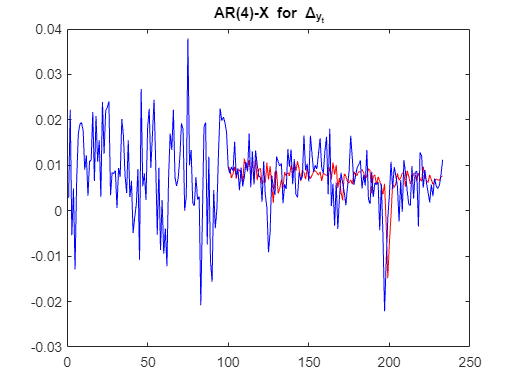

% Plot forecats for delta_yt (AR(4)-X) and actual delta_yt
plot(fore_ar_x, 'Color', 'red'); hold on;
plot(delta_yt, 'Color','blue');
title('AR(4)-X for \Delta_{y_t}');

%shhshshhhsh

% Transform AR(4)-X predictionns to log of GDP forecasts
ar_x_yt = data_rw

ar_x_yt = 234x1
    8.1403
    8.1432
    8.1654
    8.1600
    8.1649
    8.1520
    8.1587
    8.1756
    8.1946
    8.2140


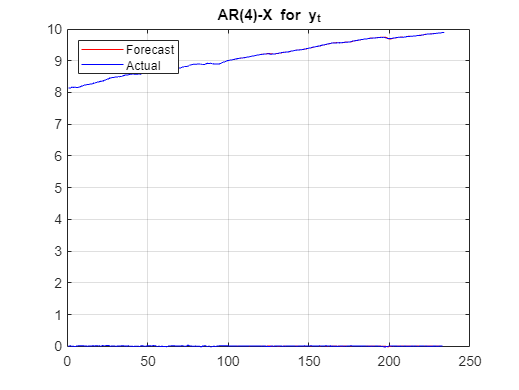


for i = length(ar_x_yt)-133:length(ar_x_yt)
    ar_x_yt(i) = data_rw(i-1) + fore_ar_x(i-1,1);
end

plot(ar_x_yt, Color="red"); hold on;
plot(data_rw, Color="blue"); hold off;
title('AR(4)-X for y_t');
legend("Forecast", "Actual", 'Location','northwest');
grid on;


ar_x_uhat = exp(actual_data_rw) - exp(ar_x_yt(end-133:end,:));
rmse_ar_x = sqrt(mean(ar_x_uhat.^2))

rmse_ar_x = 84.7605

function fore = computeForecasts(model, data, fore, title_plot)

    k = 1;
    j = 100;

    for i = 1:134
        if contains(title_plot,'VAR')
            
            fore(100+i,1:3) = forecast(estimate(model, data(k:j,:)), 1, data(k:j,:));
            
            k = k + 1;
            j = j + 1;
        else 
            model = estimate(model, data(k:j,:));
            fore(100+i) = forecast(model, 1, data(k:j,:));
    
            k = k + 1;
            j = j + 1;
        end
    end
    if contains(title_plot,'VAR') == 0
        plot(fore, Color="red"); hold on;
        plot(data, Color="blue"); hold off;
        title(title_plot);
        legend("Forecast", "Actual", 'Location','northwest');
        grid on;
    end
end
